# Subject- and Group-Level Univariate Robust Regression Analysis and Figures

Michael Sun, Ph.D.

## Housekeeping

% Check if CanlabCore Tools are installed
toolboxName = 'CANLab Core'; % Replace with the actual toolbox name
functionName = 'fmri_data'; % Replace with a function or file name from the toolbox

% Check if the function or file associated with the toolbox exists
if exist(functionName, 'file') == 2
    fprintf('%s is installed.\n', toolboxName);
else
    fprintf('%s is not installed.\n', toolboxName);
end

CANLab Core is installed.


## Load Data

load('UnivariateGLM_Workspace.mat')

## Figure Setup

close all
set(0,'DefaultFigureWindowStyle','normal');
% --- output folder for vector (SVG) figure exports ---
svgdir = fullfile(pwd, 'figures_svg');
if ~exist(svgdir,'dir'), mkdir(svgdir); end

## Configurations with Atlas/Mask

% Atlas: use labels_3 but keep labels_5 around
canlab2024 = load_atlas('canlab2024');

Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat


canlab2024.labels_5 = canlab2024.labels;
canlab2024.labels   = canlab2024.labels_3;

gray_mask = fmri_mask_image('gray_matter_mask.img');

OUT_robvoxelwise_sub = cell(9, 1);

## Run Data Metadata

disp(run_data.metadata_table)

    subjectid    condition    body_site     session    run    repetition    temp    intensity_rating    valence_rating    comfort_rating
    _________    _________    __________    _______    ___    __________    ____    ________________    ______________    ______________

        1         hot         Left Face        2        2         1           48         34.074              -12.84           41.914    
        1         hot         Left Face        4        3         2           48         35.864             -23.457           47.346    
        1         hot         Left Face        6        4         3           48          50.37             -38

## Run Subject-Level Voxelwise Regression Analysis

parfor s = 1:9   % 9 Subjects
    fprintf('Subject-%d (%d of %d)\n', s, s, 9);

    % extract from metadata_table
    sub_idx = find(run_data.metadata_table.subjectid == num2str(s));
    sub_data = run_data.metadata_table(run_data.metadata_table.subjectid == num2str(s), :);
    sessions = sub_data.session;
    body_sites = sub_data.body_site;
    conditions = sub_data.condition;
    runs = sub_data.run;
    temp = sub_data.temp;
   
    % Group by condition × body_site
    [G, ~, ~] = findgroups(sub_data.condition, sub_data.body_site);
    
    for k = 1:numel(colsToImpute)
        colname = colsToImpute(k);
    
        % Compute mean within each group, ignoring NaNs
        groupMeans = splitapply(@nanmean, sub_data.(colname), G);  % one mean per group
    
        % Map group means back to each row
        mean_for_row = groupMeans(G);
    
        % Replace NaNs with the appropriate group mean
        nan_idx = isnan(sub_data.(colname));
        sub_data.(colname)(nan_idx) = mean_for_row(nan_idx);
    end

    % Centered continuous covariates: sessions, runs, high temp
    sessions_z = sessions - 1;      % 0-based index
    runs_z     = runs     - 1;

    sessions_z = sessions_z - mean(sessions_z);
    runs_z     = runs_z     - mean(runs_z);

    % Orthogonal contrast coding of bodysite (8 sites)
    site_dummies_raw = dummyvar(body_sites);   % N × 8
    num_sites        = size(site_dummies_raw, 2);

    bodysiteX = create_orthogonal_contrast_set(num_sites);  % user function
    site_dummies = site_dummies_raw * bodysiteX';           % still N × 8 (or 7, depending on bodysiteX)

    % Optionally check orthogonality / balance
    check_orthogonality_and_balance(site_dummies, 'bodysite orthogonal contrasts');

    % 1. Check for Orthogonality
    % Compute the dot product of each pair of columns (contrasts)
    orthogonality_check = site_dummies' * site_dummies;
    disp('Orthogonality Check (Dot Products):');
    disp(orthogonality_check);
    
    % Check if off-diagonal elements are close to zero
    off_diagonal_elements = orthogonality_check - diag(diag(orthogonality_check));
    is_orthogonal = all(abs(off_diagonal_elements(:)) < 1e-10); % Adjust tolerance as needed
    if is_orthogonal
        disp('The coding scheme is orthogonal.');
    else
        disp('The coding scheme is not orthogonal.');
    end
    
    % 2. Check for Balance
    % Sum of each column should be zero
    column_sums = sum(site_dummies, 1);
    disp('Column Sums (should be close to zero):');
    disp(column_sums);
    
    is_balanced = all(abs(column_sums) < 1e-10); % Adjust tolerance as needed
    if is_balanced
        disp('The coding scheme is balanced.');
    else
        disp('The coding scheme is not balanced.');

        % Assume new_coding_scheme is the resulting coding scheme from previous step
        
        % 1. Calculate the mean of each column
        column_means = mean(site_dummies, 1);
        
        % 2. Subtract the mean from each element to center the columns around zero
        site_dummies = site_dummies - column_means;
        
        % Display the adjusted (balanced) coding scheme
        disp('Adjusted (Balanced) Coding Scheme:');
        disp(site_dummies);
        
        % Verify if the adjusted coding scheme is balanced
        column_sums_adjusted = sum(site_dummies, 1);
        disp('Column Sums of Adjusted Coding Scheme (should be close to zero):');
        disp(column_sums_adjusted);
        
        is_balanced_adjusted = all(abs(column_sums_adjusted) < 1e-10); % Adjust tolerance as needed
        if is_balanced_adjusted
            disp('The adjusted coding scheme is balanced.');
        else
            disp('The adjusted coding scheme is not balanced.');
        end
    end
    
    % 3. Check for Multicollinearity
    % Check if the design matrix has full rank
    rank_of_matrix = rank(site_dummies);
    expected_rank = size(site_dummies, 2); % Number of contrasts
    
    if rank_of_matrix == expected_rank
        disp('The coding scheme has full rank and is appropriate for regression.');
    else
        disp(['The coding scheme does not have full rank. Rank: ' num2str(rank_of_matrix)]);
    end

    % Condition dummy coding (warm ref)
    conditions = reordercats(conditions, {'warm', 'hot', 'imagine'});
    cond_dummies_raw = dummyvar(conditions);       % N × 3 (warm,hot,imagine)
    cond_dummies     = cond_dummies_raw(:,2:end);      % drop warm -> columns: Hot-Warm, Imagine-Warm
    condition_names  = {'Hot-Warm', 'Imagine-Warm'};   % 2 columns

    % Bodysite contrast names (match number of columns in site_dummies)
    % Adjust these names to match your create_orthogonal_contrast_set output:
    bs_names = { ...
        'abd v che', ...
        '1-2 v larm', ...
        '1-3 v lface', ...
        '1-4 v lleg', ...
        '1-5 v rarm', ...
        '1-6 v rface', ...
        '1-7 v rleg'};   % add/remove to match size(site_dummies,2)

    bs_names = bs_names(1:size(site_dummies,2));  % truncate safely if needed

    X = [sessions_z, site_dummies, runs_z, cond_dummies];
    Xnames = [{ 'sessions'}, bs_names, { 'runs' }, condition_names];

    %% --------------------------------------------------------------------
    %  4 Load / preprocess images, attach design, run regress() robust voxelwise
    % ---------------------------------------------------------------------
    sub_fmridat     = get_wh_image(run_data, sub_idx);
    sub_fmridat     = preprocess(sub_fmridat, 'smooth', 6);
    sub_fmridat     = apply_mask(sub_fmridat, gray_mask);
    % sub_fmridat.X   = X;


    [group_metrics individual_metrics values gwcsf gwcsfmean gwcsfl2norm] = qc_metrics_second_level(sub_fmridat);
    sub_fmridat.X   = [X, values(:, 2:3)];
    Xnames = [Xnames, 'White Matter', 'CSF'];

    OUT_robvoxelwise_sub{s} = regress(sub_fmridat, .05, 'fdr', ...
                                'variable_names', Xnames, ...
                                'analysis_name', ['Subject-', num2str(s), ' Second-Level'], ...
                                'robust', ...
                                'display');
end

Subject-3 (3 of 9)

=== bodysite orthogonal contrasts: orthogonality / balance check ===
Dot products (X'X):
           30            0   1.1102e-16            0   5.5511e-17  -5.5511e-17            0
            0         28.5           -2         -1.5         -1.2           -1     -0.85714
   1.1102e-16           -2       20.667          0.5          0.4      0.33333      0.28571
            0         -1.5          0.5       25.125         -0.9        -0.75     -0.64286
   5.5511e-17         -1.2          0.4         -0.9        24.48         -0.6     -0.51429
  -5.5511e-17           -1      0.33333        -0.75         -0.6           21    6.582e-16
            0     -0.85714      0.28571     -0.64286     -0.51429    6.582e-16       17.571

Column sums:
            0           -6            2         -4.5         -3.6   5.5511e-16            3

Rank: 7 (expected 7)
 -> Columns are NOT orthogonal.
 -> Columns are NOT balanced (summing columns to zero may be desirable).

## Run Group-Level Voxelwise Regression

First, concatenate the Subject Level Images

for s = 1:9
    hw_idx = find(strcmp(OUT_robvoxelwise_sub{s}.variable_names, 'HotWarm'));
    iw_idx = find(strcmp(OUT_robvoxelwise_sub{s}.variable_names, 'ImagineWarm'));

    hw_vox_t{s} = get_wh_image(OUT_robvoxelwise_sub{s}.t, hw_idx);
    iw_vox_t{s} = get_wh_image(OUT_robvoxelwise_sub{s}.t, iw_idx);


    if s == 1
        hw_vox_beta = fmri_data(get_wh_image(OUT_robvoxelwise_sub{s}.b, hw_idx));
        iw_vox_beta = fmri_data(get_wh_image(OUT_robvoxelwise_sub{s}.b, iw_idx));
    else
        hw_vox_beta = cat(hw_vox_beta, fmri_data(get_wh_image(OUT_robvoxelwise_sub{s}.b, hw_idx)));
        iw_vox_beta = cat(iw_vox_beta, fmri_data(get_wh_image(OUT_robvoxelwise_sub{s}.b, iw_idx)));

    end
end

Then perform the group-level regression.

w = warning ('off','all');

hw_vox_beta.removed_voxels = [];
hw_vox_beta.removed_images = [];

iw_vox_beta.removed_voxels = [];
iw_vox_beta.removed_images = [];

hw_vox_beta_sm6 = preprocess(hw_vox_beta, 'smooth', 6);
iw_vox_beta_sm6 = preprocess(iw_vox_beta, 'smooth', 6);

Exp_Pain = regress(hw_vox_beta_sm6, .05, 'fdr', 'analysis_name', 'Level 3 Group-Level Robust Voxelwise', 'robust', 'display');
Img_Pain = regress(iw_vox_beta_sm6, .05, 'fdr', 'analysis_name', 'Level 3 Group-Level Robust Voxelwise', 'robust', 'display');


Img_Pain = regress(iw_vox_beta, .05, 'fdr', 'analysis_name', 'Level 3 Group-Level Robust Voxelwise', 'robust', 'display');

## Analyze Results

### Experienced Pain Results

[~,~,~,~,~,~,t]=threshold(Exp_Pain.t, .05, 'fdr').table_of_atlas_regions_covered('atlas', canlab2024, 'coverage', 0);

Image   1 FDR q < 0.050 threshold is 0.008669

Image   1
158 contig. clusters, sizes   1 to 13411
Positive effect: 7178 voxels, min p-value: 0.00000005
Negative effect: 10133 voxels, min p-value: 0.00000001
Atlas name: CANLab2024_MNI152NLin2009cAsym_coarse_2mm
Coverage threshold: 0.0%


Positive Effects

                   Region                   Coverage    Voxels_in_region    Atlas_index_number    mean_in_region    max_abs_in_region                  labels_2                                labels_3                                                                 labels_4                                                           labels_5                atlas_mm_coords    
    ____________________________________    ________    ________________    

sortrows(t(t.Coverage > 0,:), {'mean_in_region', 'Coverage'}, {'descend','descend'})

ans = 444×10 table
              Region               Coverage    Voxels_in_region    Atlas_index_number    mean_in_region    max_abs_in_region                labels_2                          labels_3                                  labels_4                            labels_5    
    ___________________________    ________    ________________    __________________    ______________    _________________    _________________________________    ___________________________    _________________________________________________    _______________

    {'insula_operculum_L'     }     98.765           162                  114                8.3222           

[exp_pain_rpos, exp_pain_rneg, exp_pain_rtbl] = region(threshold(Exp_Pain.t, .05, 'fdr')).table('subdivide', 'atlas_obj', canlab2024);

Image   1 FDR q < 0.050 threshold is 0.008669

Image   1
158 contig. clusters, sizes   1 to 13411
Positive effect: 7178 voxels, min p-value: 0.00000005
Negative effect: 10133 voxels, min p-value: 0.00000001
Grouping contiguous voxels: 158 regions

____________________________________________________________________________________________________________________________________________
Positive Effects
                   Region                     Volume              XYZ             minP                    modal_label_descriptions                    Perc_covered_by_label    Atlas_regions_covered    region_index
    ____________________________________    __________    ___________________    ______    _______________________________________________________    __

Compressed NIfTI files are not supported.


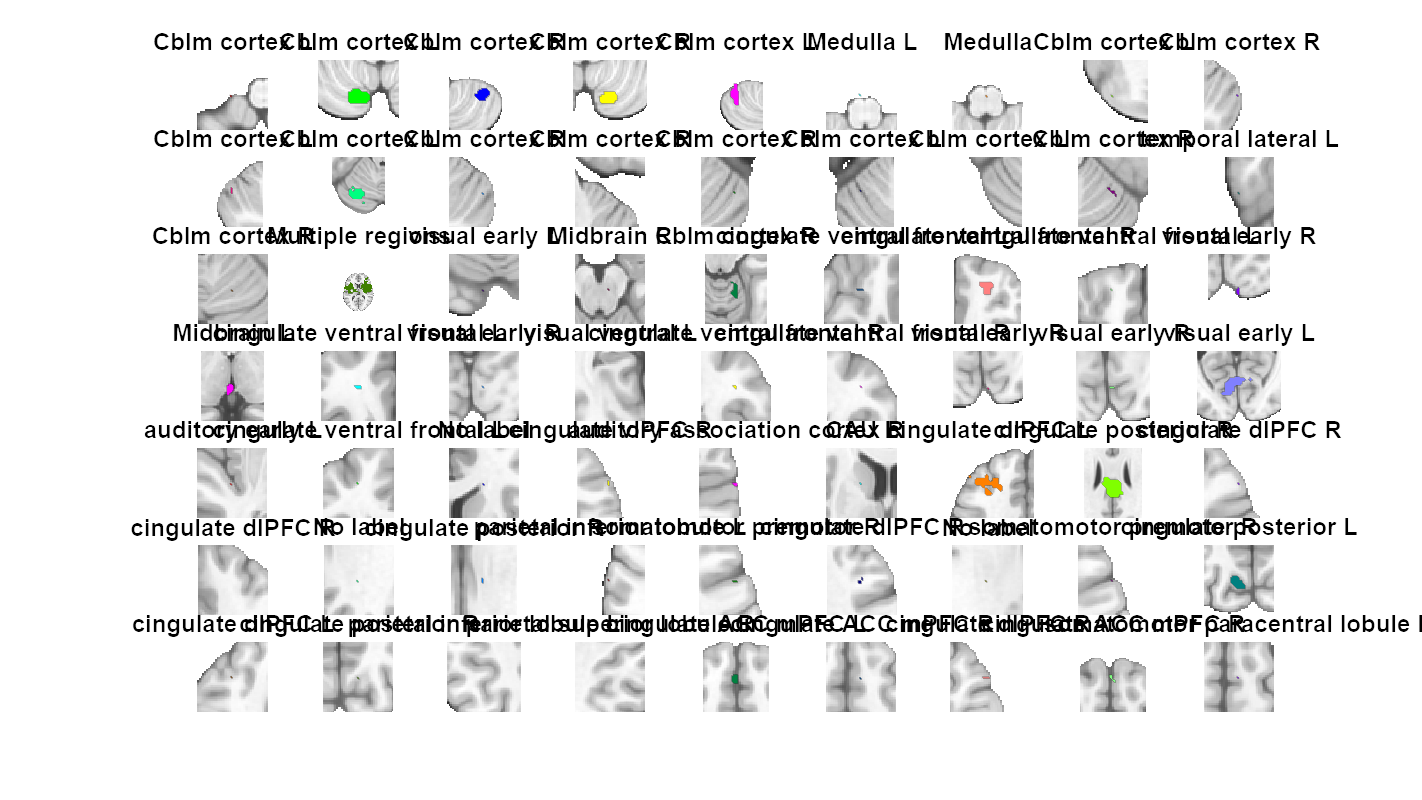

figure; autolabel_regions_using_atlas(exp_pain_rpos, canlab2024).montage('regioncenters');

### Imagined Pain Results

[~,~,~,~,~,~,t]=threshold(Img_Pain.t, .05, 'fdr').table_of_atlas_regions_covered('atlas', canlab2024, 'coverage', 0);

Image   1 FDR q < 0.050 threshold is 0.000170

Image   1
120 contig. clusters, sizes   1 to  58
Positive effect:  91 voxels, min p-value: 0.00000006
Negative effect: 248 voxels, min p-value: 0.00000034
Atlas name: CANLab2024_MNI152NLin2009cAsym_coarse_2mm
Coverage threshold: 0.0%


Positive Effects

                   Region                   Coverage    Voxels_in_region    Atlas_index_number    mean_in_region    max_abs_in_region                labels_2                               labels_3                                      labels_4                                 labels_5                atlas_mm_coords    
    ____________________________________    ________    ________________    __________________    ______________

sortrows(t(t.Coverage > 0,:), {'mean_in_region', 'Coverage'}, {'descend','descend'})

ans = 112×10 table
              Region               Coverage    Voxels_in_region    Atlas_index_number    mean_in_region    max_abs_in_region               labels_2                         labels_3                                  labels_4                                labels_5        
    ___________________________    ________    ________________    __________________    ______________    _________________    _______________________________    ___________________________    _________________________________________________    _______________________

    {'insula_anterior_L'      }     0.31646           316                 110                12.87

[img_pain_rpos, img_pain_rneg, img_pain_rtbl] = region(threshold(Img_Pain.t, .05, 'fdr')).table('subdivide', 'atlas_obj', canlab2024);

Image   1 FDR q < 0.050 threshold is 0.000170

Image   1
120 contig. clusters, sizes   1 to  58
Positive effect:  91 voxels, min p-value: 0.00000006
Negative effect: 248 voxels, min p-value: 0.00000034
Grouping contiguous voxels: 120 regions

____________________________________________________________________________________________________________________________________________
Positive Effects
                   Region                   Volume           XYZ            minP                                                                                                                                                                                       modal_label_descriptions                                                                                                                                                                                      Perc_covered_by_label    

Compressed NIfTI files are not supported.


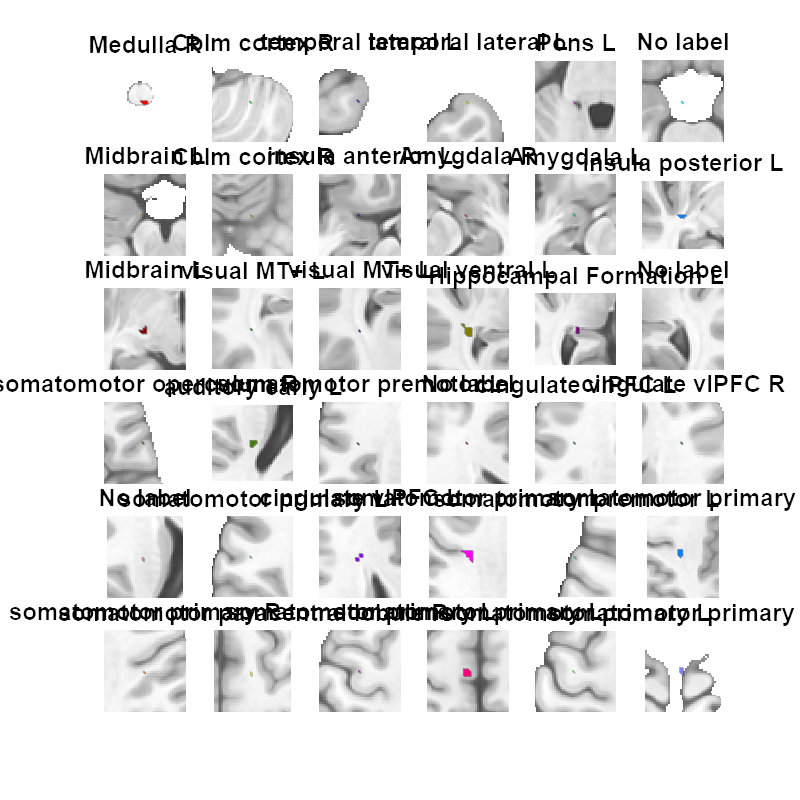

figure; autolabel_regions_using_atlas(img_pain_rpos, canlab2024).montage('regioncenters');

## Visualize Results

### Figure 3A: Group-Level Experienced Pain (Hot-Warm)

Final surface plots generated in MRICroGL.

figure('Position', [0 0 1080 720]);
o2 = montage(threshold(Exp_Pain.t, .05, 'fdr'), 'leftright inout subcortex', 'gray_buffer', false); sgtitle('Hot-Warm'); drawnow; snapnow; 

Image   1 FDR q < 0.050 threshold is 0.008669

Image   1
158 contig. clusters, sizes   1 to 13411
Positive effect: 7178 voxels, min p-value: 0.00000005
Negative effect: 10133 voxels, min p-value: 0.00000001
Setting up fmridisplay objects
Compressed NIfTI files are not supported.
Anatomical image: Adapted from the 7T high-resolution atlas of Keuken, Forstmann et al.                                                                                                                                             
Keuken et al. (2014). Quantifying inter-individual anatomical variability in the subcortex using 7T structural MRI.                                                                                                                 
Forstmann, Birte U., Max C. Keuken, Andreas Schafer, Pierre-Louis Bazin, Anneke Alkemade, and Robert Turner. 2014. ?Multi-Modal Ultra-High Resolution Structural 7-Tesla MRI Data Repository.? Scientific Data 1 (December): 140050.
Anatomical image: Adapted from th

sagittal montage: 1835 voxels displayed, 15476 not displayed on these slices


coronal montage: 2960 voxels displayed, 14351 not displayed on these slices


axial montage: 2622 voxels displayed, 14689 not displayed on these slices


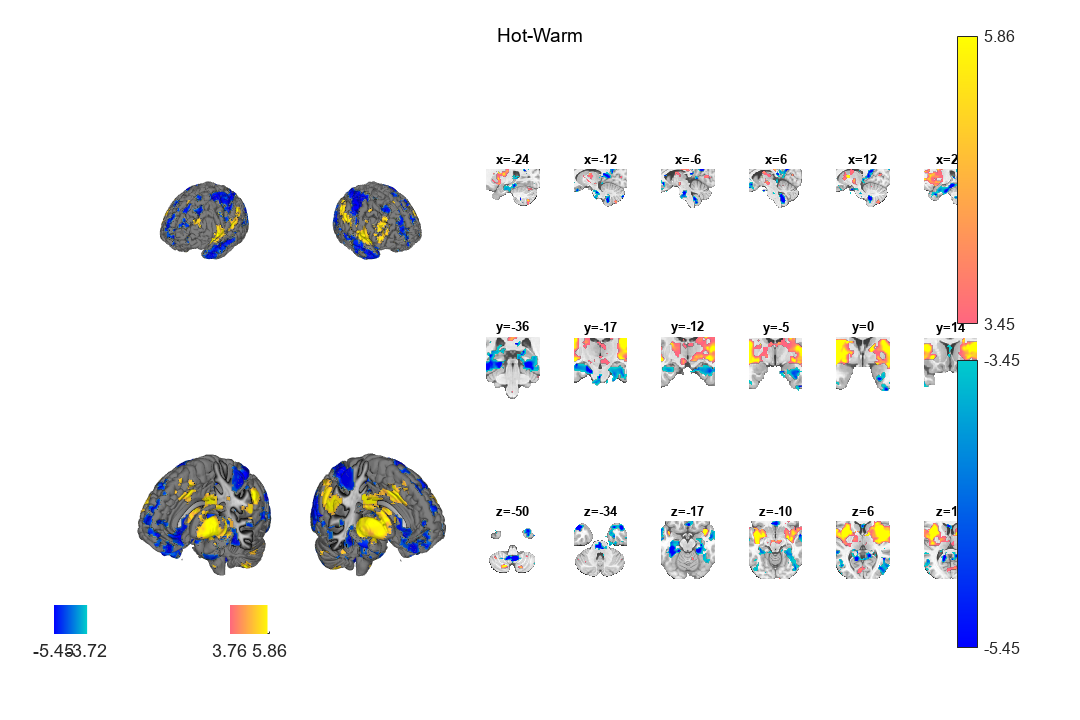

colorbar off
delete(o2.activation_maps{1}.legendhandle); % Remove the annoying occluding colorbar

close all;

figure('Position', [0 0 1080 720]);
o2 = montage(threshold(Exp_Pain.t, .05, 'fdr'), 'subcortex compact', 'gray_buffer', false, 'trans', 'transvalue', .5); sgtitle('Hot-Warm'); drawnow; snapnow;

Image   1 FDR q < 0.050 threshold is 0.008669

Image   1
158 contig. clusters, sizes   1 to 13411
Positive effect: 7178 voxels, min p-value: 0.00000005
Negative effect: 10133 voxels, min p-value: 0.00000001
Setting up fmridisplay objects
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Problem displaying title montage for statistic_image object


sagittal montage: 231 voxels displayed, 17080 not displayed on these slices


sagittal montage: 307 voxels displayed, 17004 not displayed on these slices


sagittal montage: 264 voxels displayed, 17047 not displayed on these slices


axial montage: 165 voxels displayed, 17146 not displayed on these slices


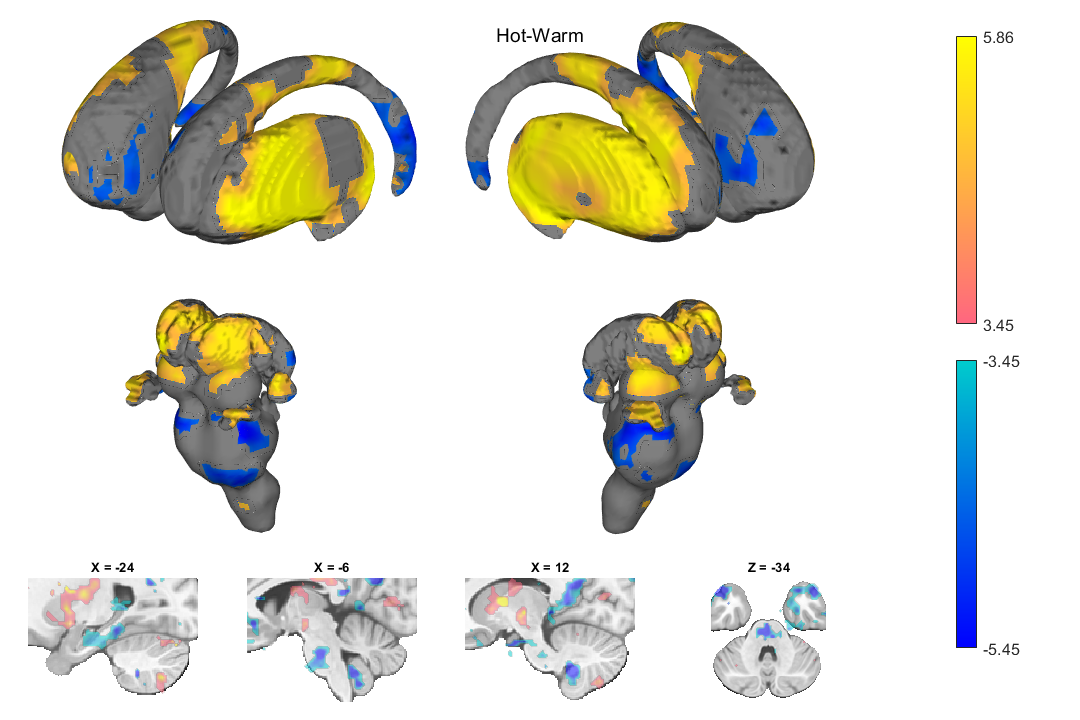

colorbar off
delete(o2.activation_maps{1}.legendhandle); % Remove the annoying occluding colorbar

### Write out nifti image to be visualized in MRICroGL

Exp_Pain.t.write('fname', 'ExpPain_t.nii', 'overwrite');

Writing: 
ExpPain_t.nii


### Figure 3B: Subject-Level Experienced Pain (Hot-Warm)

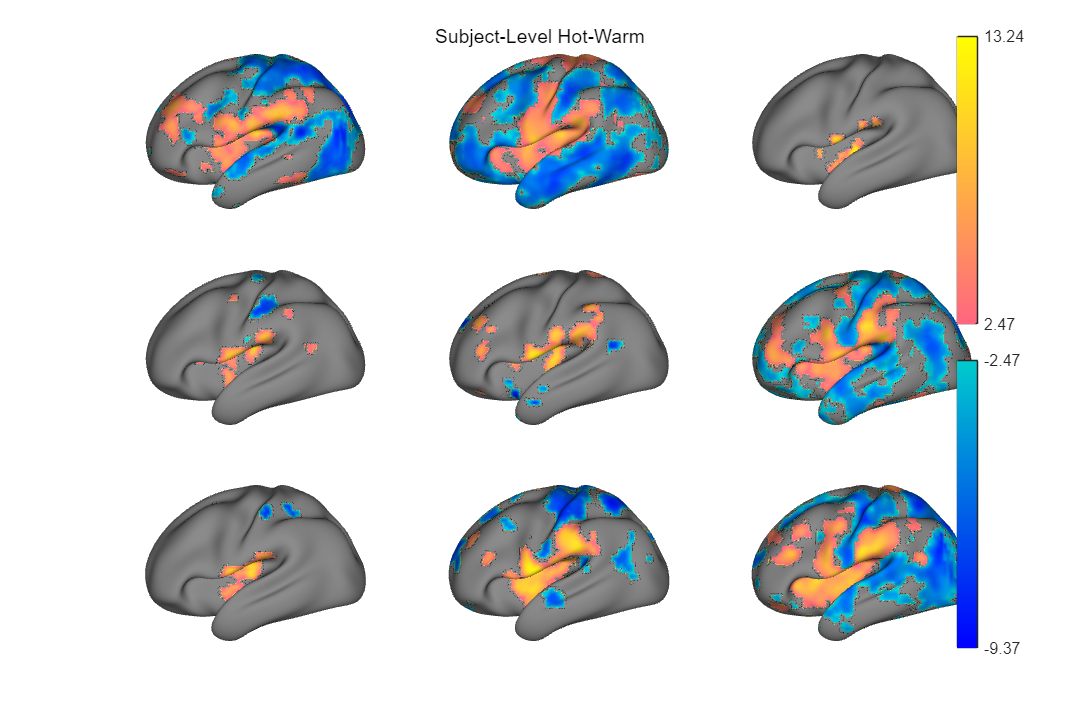

figure('Position', [0 0 1080 720]);

for s = 1:9
    data = hw_vox_t{s};
    
    subplot(3,3,s)
    data.surface('hcp inflated left', 'existingfig', 'gray_buffer', false);

    % If you wanted to flip it around
    % p1=addbrain('hcp inflated right');
    % view(-270, 0); lightRestoreSingle;
    % data.surface('surface_handles', p1, 'existingfig', 'clim', [0 9]);

end

sgtitle('Subject-Level Hot-Warm')

### Figure 3C: Group-Level Experienced Pain (Imagine-Warm)

figure('Position', [0 0 1080 720]);
o2 = montage(threshold(Img_Pain.t, .05, 'fdr'), 'leftright inout subcortex', 'gray_buffer', false); sgtitle('Imagine-Warm'); drawnow; snapnow; 

Image   1 FDR q < 0.050 threshold is 0.000170

Image   1
120 contig. clusters, sizes   1 to  58
Positive effect:  91 voxels, min p-value: 0.00000006
Negative effect: 248 voxels, min p-value: 0.00000034
Setting up fmridisplay objects
Compressed NIfTI files are not supported.
Anatomical image: Adapted from the 7T high-resolution atlas of Keuken, Forstmann et al.                                                                                                                                             
Keuken et al. (2014). Quantifying inter-individual anatomical variability in the subcortex using 7T structural MRI.                                                                                                                 
Forstmann, Birte U., Max C. Keuken, Andreas Schafer, Pierre-Louis Bazin, Anneke Alkemade, and Robert Turner. 2014. ?Multi-Modal Ultra-High Resolution Structural 7-Tesla MRI Data Repository.? Scientific Data 1 (December): 140050.
Anatomical image: Adapted from the 7T 

sagittal montage:  23 voxels displayed, 316 not displayed on these slices


coronal montage:  49 voxels displayed, 290 not displayed on these slices


axial montage:  62 voxels displayed, 277 not displayed on these slices


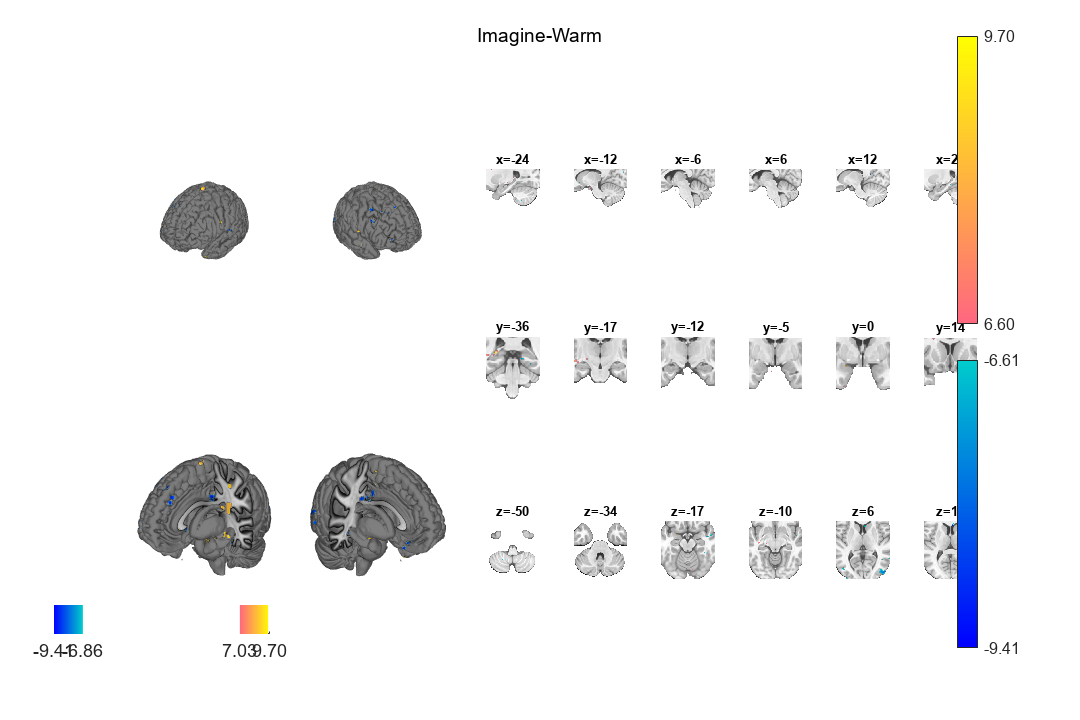

colorbar off
delete(o2.activation_maps{1}.legendhandle); % Remove the annoying occluding colorbar

 close all;

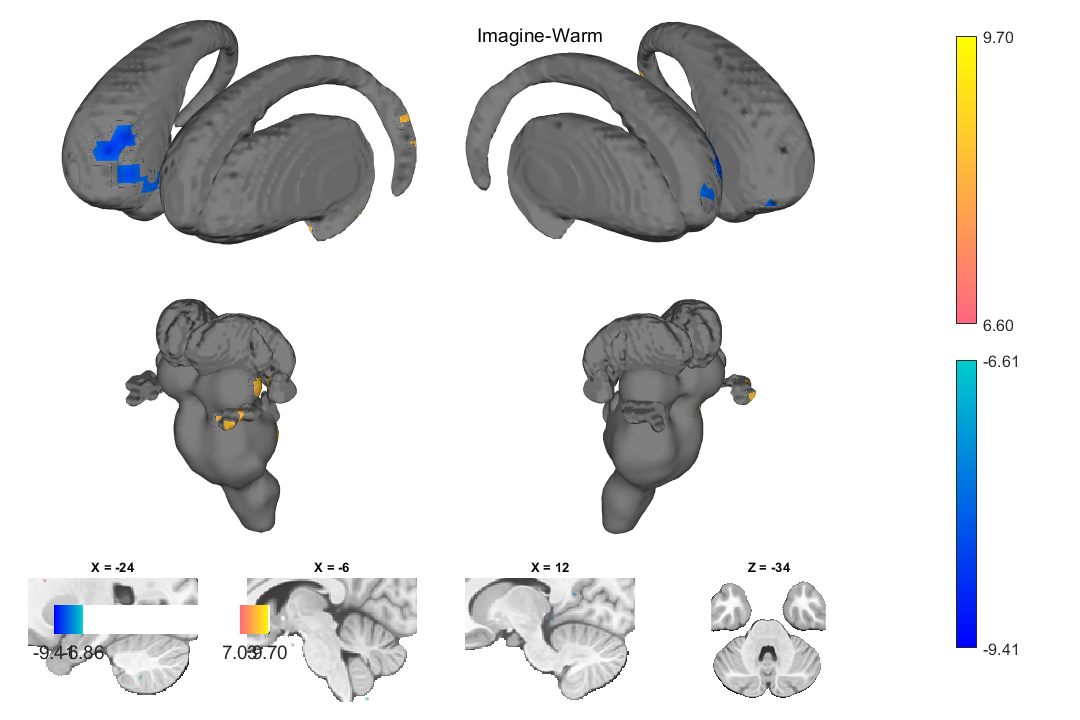

Image   1 FDR q < 0.050 threshold is 0.000170

Image   1
120 contig. clusters, sizes   1 to  58
Positive effect:  91 voxels, min p-value: 0.00000006
Negative effect: 248 voxels, min p-value: 0.00000034
Setting up fmridisplay objects
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Problem displaying title montage for statistic_image object


sagittal montage:   4 voxels displayed, 335 not displayed on these slices


sagittal montage:   3 voxels displayed, 336 not displayed on these slices


sagittal montage:   5 voxels displayed, 334 not displayed on these slices


axial montage:   0 voxels displayed, 339 not displayed on these slices


figure('Position', [0 0 1080 720]);
montage(threshold(Img_Pain.t, .05, 'fdr'), 'subcortex compact', 'gray_buffer', false, 'trans', 'transvalue', .5); sgtitle('Imagine-Warm'); drawnow; snapnow;

### Write out nifti image to be visualized in MRICroGL

Img_Pain.t.write('fname', 'ImgPain_t.nii', 'overwrite');

Writing: 
ImgPain_t.nii


### Figure 3D: Subject-Level Imagined Pain (Imagine-Warm)

figure('Position', [0 0 1080 720]);

for s = 1:9
    data = iw_vox_t{s};
    
    subplot(3,3,s)
    data.surface('hcp inflated left', 'existingfig', 'gray_buffer', false);

    % If you wanted to flip it around
    % p1=addbrain('hcp inflated right');
    % view(-270, 0); lightRestoreSingle;
    % data.surface('surface_handles', p1, 'existingfig', 'clim', [0 9]);

    drawnow;
    snapnow;
    % close all;

end

No data to display. Returning


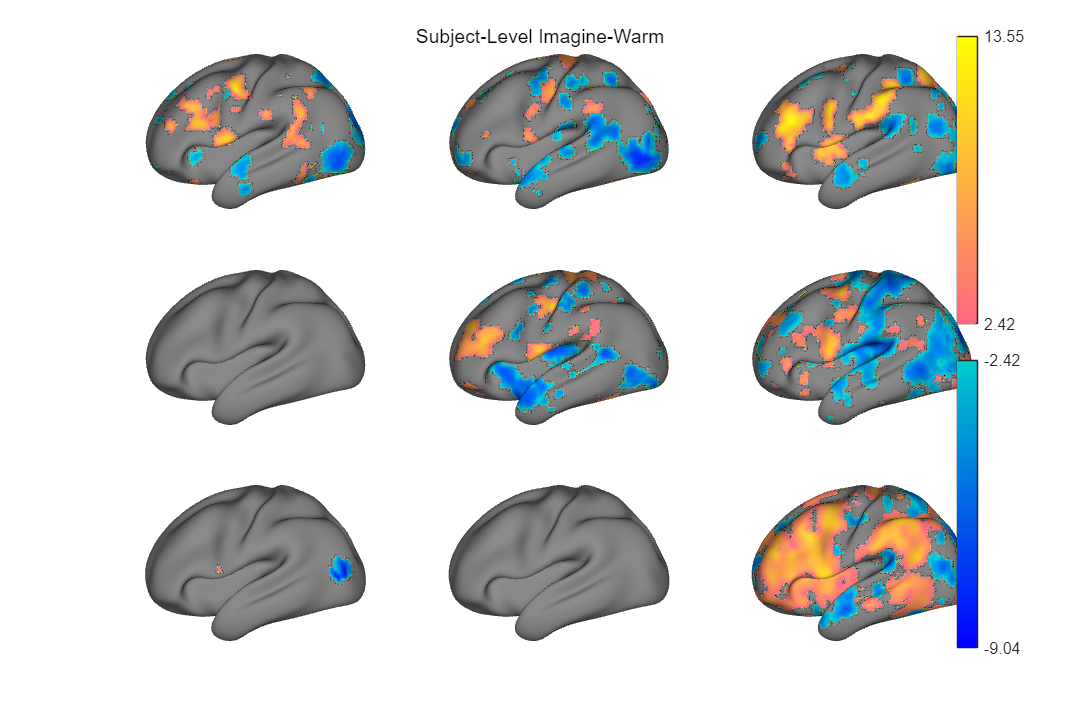

sgtitle('Subject-Level Imagine-Warm')

### Figure 3F: Barplots

w = warning ('off','all');
% -------------------------------------------------------------------------
% Precompute ROI indices (done once)
% -------------------------------------------------------------------------
idx_LBA43   = strcmp(canlab2024.labels_5, 'Ctx_43_L');
idx_RBA43   = strcmp(canlab2024.labels_5, 'Ctx_43_R');
idx_dpIns_Pain = strcmp(PainROIs_atlas.labels,   'dpIns');

roi_short = {'LBA43', 'RBA43', 'dpIns'};

% Condition definitions
cond_info(1).name = 'HotWarm';
cond_info(1).idx  = hw_idx;

cond_info(2).name = 'ImagineWarm';
cond_info(2).idx  = iw_idx;

nSub  = 9;
nCond = numel(cond_info);

rows = {};   % will hold {subject, ROI, condition, mean, ste}

% -------------------------------------------------------------------------
% Main loop: subject × condition
% -------------------------------------------------------------------------
for s = 1:nSub

    for c = 1:nCond
        cond_name = cond_info(c).name;
        img_idx   = cond_info(c).idx;

        % Extract data for this subject & condition
        [b1, ~, ~, ~, ~, ~, ste1] = extract_data(PainROIs_atlas, ...
            get_wh_image(OUT_robvoxelwise_sub{s}.b, img_idx));

        [b2, ~, ~, ~, ~, ~, ste2] = extract_data(canlab2024, ...
            get_wh_image(OUT_robvoxelwise_sub{s}.b, img_idx));

        % ROI values
        m_LBA43  = b2(idx_LBA43);
        se_LBA43 = ste2(idx_LBA43);

        m_RBA43  = b2(idx_RBA43);
        se_RBA43 = ste2(idx_RBA43);

        m_dpIns  = b1(idx_dpIns_Pain);
        se_dpIns = ste1(idx_dpIns_Pain);

        % Append rows: Amyg, dpIns, SMA (order matches roi_short)
        rows(end+1,:) = {s, 'LBA43', cond_name, m_LBA43,  se_LBA43};
        rows(end+1,:) = {s, 'RBA43', cond_name, m_RBA43,  se_RBA43};
        rows(end+1,:) = {s, 'dpIns',cond_name, m_dpIns, se_dpIns};
    end
end

Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


Resampling data object to space defined by atlas object.


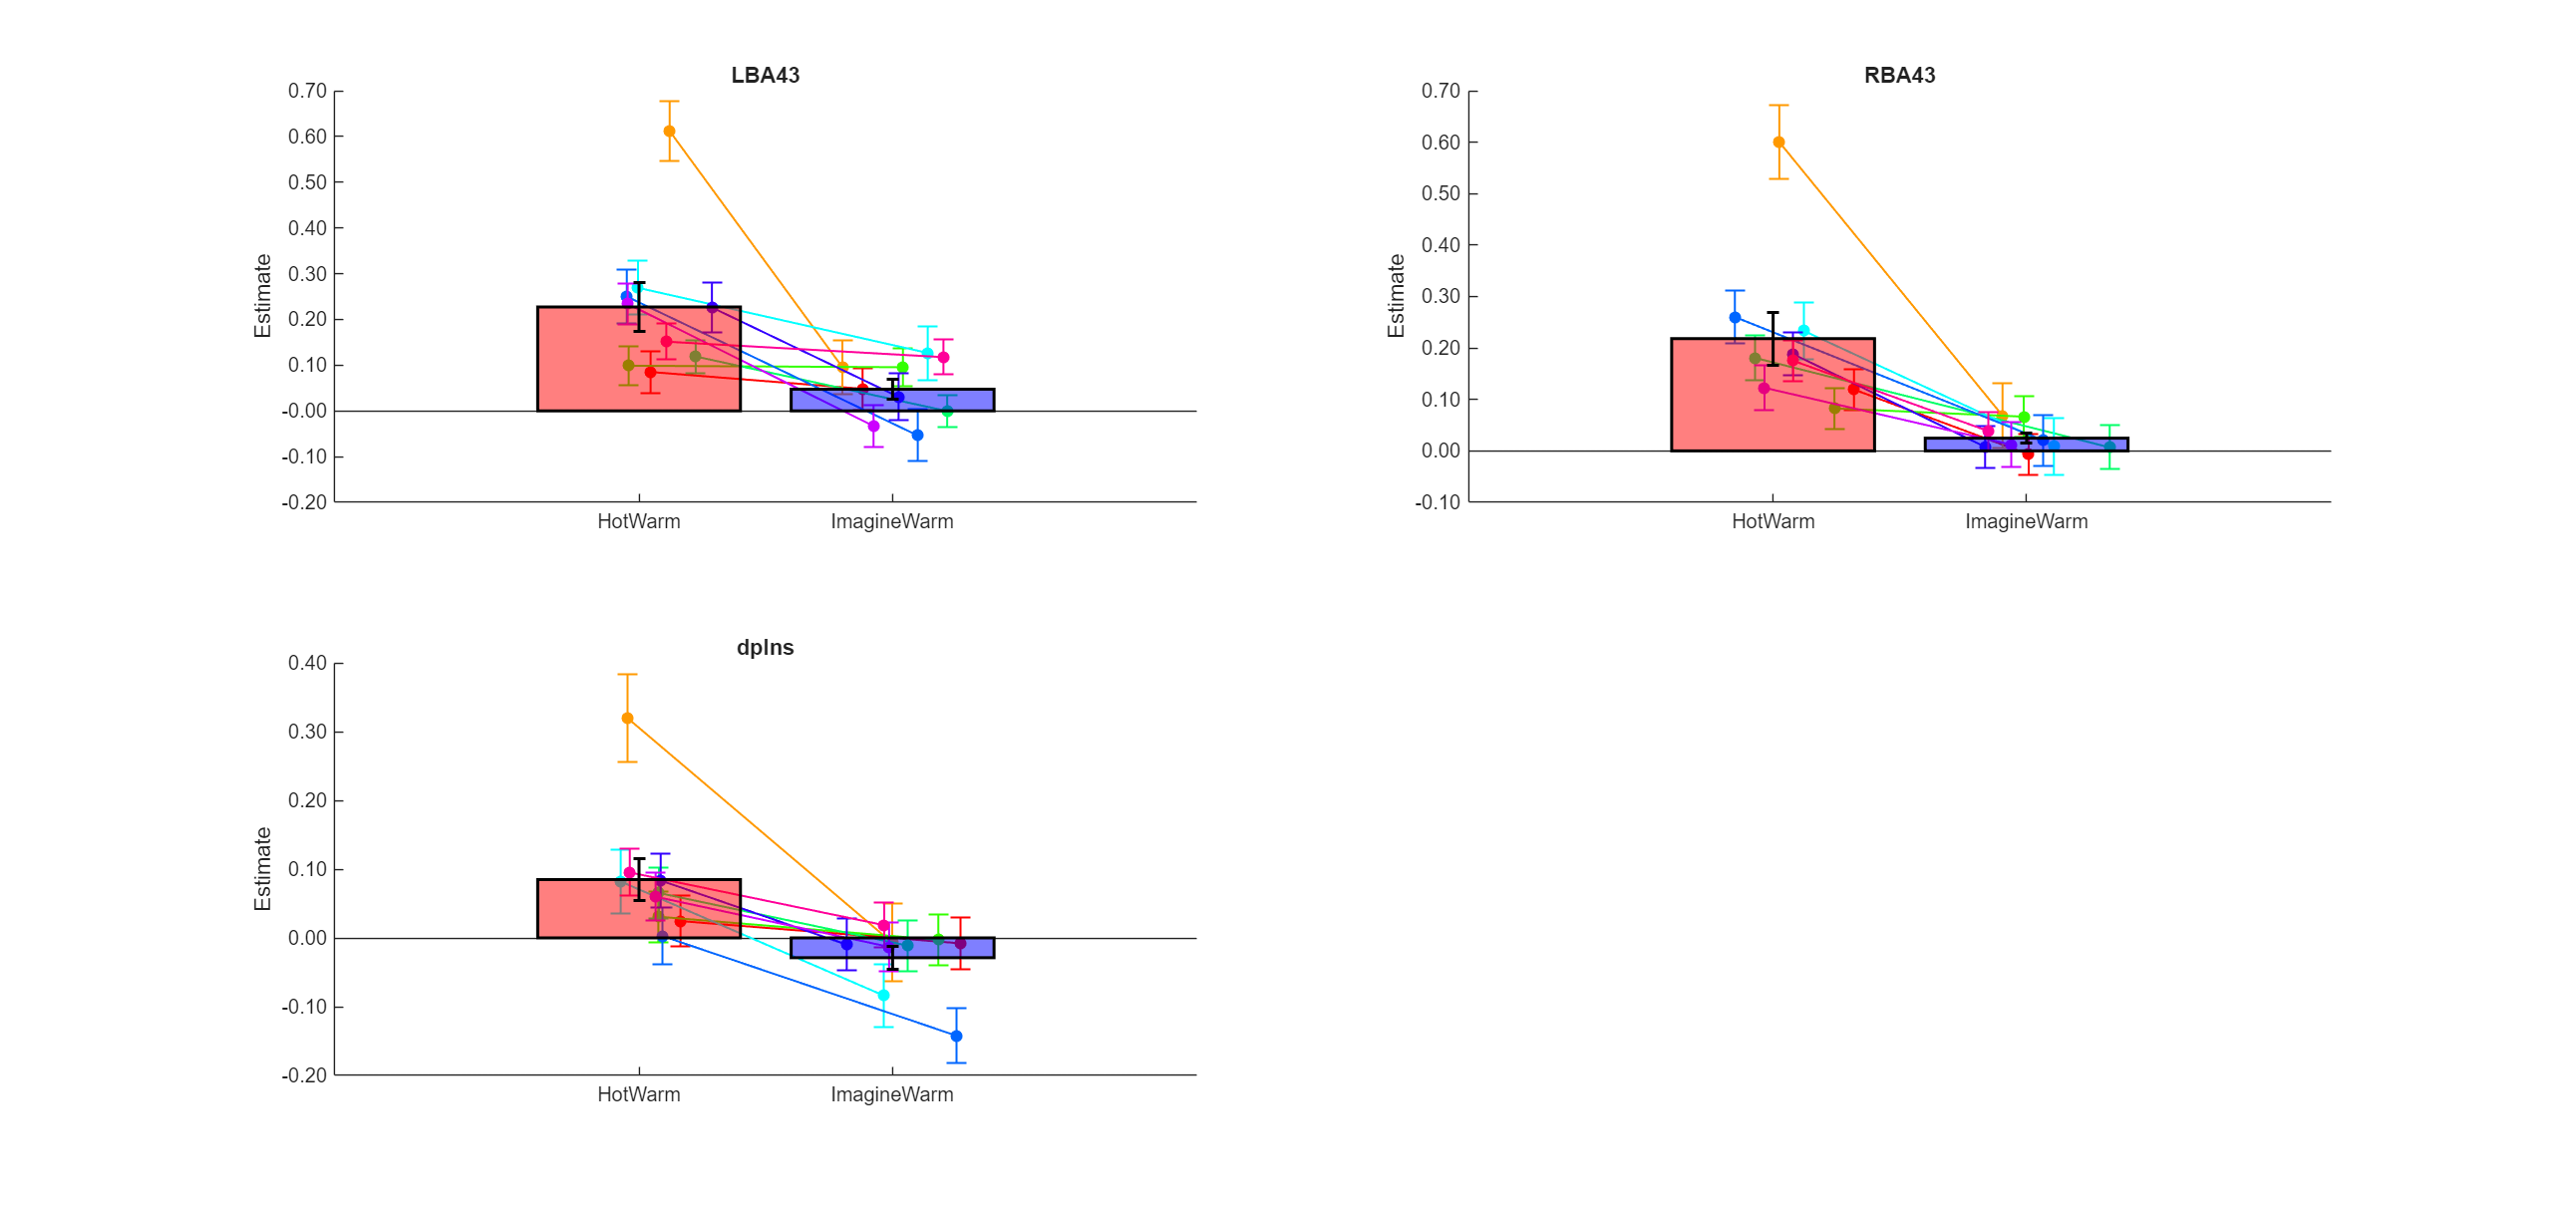

% -------------------------------------------------------------------------
% Convert to table
% -------------------------------------------------------------------------
T = cell2table(rows, ...
    'VariableNames', {'subject','ROI','condition','mean','ste'});

[grand_means, grand_se] = plot_subject_roi_means( ...
    T, {'LBA43','RBA43','dpIns'}, {'HotWarm','ImagineWarm'});
print(gcf, fullfile(svgdir, 'Figure_3F_ROI_Barplots.svg'), '-dsvg', '-vector');   % vector SVG export

### Barplot Legend

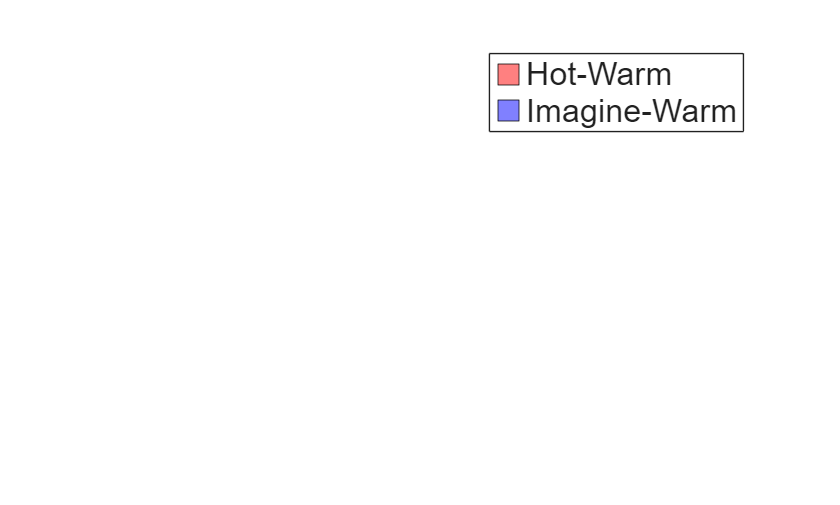

han = makelegend({'Hot-Warm', 'Imagine-Warm'}, {[1 0.5 0.5], [0.5 0.5 1]});
set(han, 'FontName', 'Helvetica', 'FontWeight', 'light');
print(gcf, fullfile(svgdir, 'Figure_3F_legend.svg'), '-dsvg', '-vector');   % vector SVG export

## Supplementary Figure 4: Participant-level experienced pain contrast (Hot-Warm)

Compressed NIfTI files are not supported.
Image   1 FDR q < 0.050 threshold is 0.013313

Image   1
162 contig. clusters, sizes   1 to 20204
Positive effect: 7691 voxels, min p-value: 0.00000000
Negative effect: 16714 voxels, min p-value: 0.00000000
Grouping contiguous voxels: 162 regions
Image   1 FDR q < 0.050 threshold is 0.022194

Image   1
 75 contig. clusters, sizes   1 to 38591
Positive effect: 22589 voxels, min p-value: 0.00000000
Negative effect: 18102 voxels, min p-value: 0.00000000
Grouping contiguous voxels:  75 regions
Image   1 FDR q < 0.050 threshold is 0.000305

Image   1
 18 contig. clusters, sizes   1 to 240
Positive effect: 539 voxels, min p-value: 0.00000000
Negative effect:  25 voxels, min p-value: 0.00002613
Grouping contiguous voxels:  18 regions
Image   1 FDR q < 0.050 threshold is 0.001858

Image   1
102 contig. clusters, sizes   1 to 799
Positive effect: 2042 voxels, min p-value: 0.00000000
Negative effect: 1365 voxels, min p-value: 0.00000002
Grouping contiguo

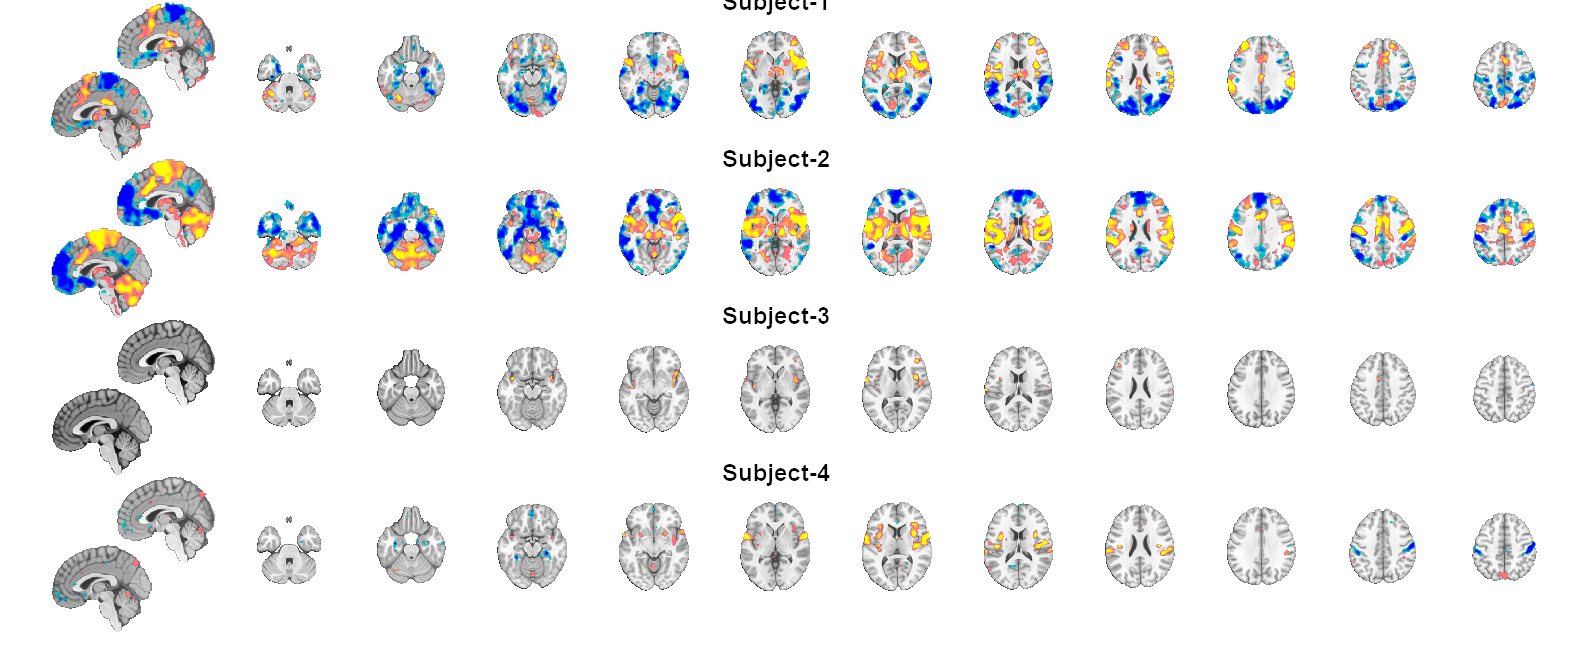

Image   1 FDR q < 0.050 threshold is 0.001960

Image   1
 78 contig. clusters, sizes   1 to 968
Positive effect: 2792 voxels, min p-value: 0.00000000
Negative effect: 802 voxels, min p-value: 0.00001127
Grouping contiguous voxels:  78 regions
Image   1 FDR q < 0.050 threshold is 0.015024

Image   1
136 contig. clusters, sizes   1 to 23187
Positive effect: 10079 voxels, min p-value: 0.00000000
Negative effect: 17471 voxels, min p-value: 0.00000000
Grouping contiguous voxels: 136 regions
Image   1 FDR q < 0.050 threshold is 0.000763

Image   1
 25 contig. clusters, sizes   1 to 638
Positive effect: 1278 voxels, min p-value: 0.00000000
Negative effect: 139 voxels, min p-value: 0.00000273
Grouping contiguous voxels:  25 regions
Image   1 FDR q < 0.050 threshold is 0.007292

Image   1
136 contig. clusters, sizes   1 to 6399
Positive effect: 5945 voxels, min p-value: 0.00000000
Negative effect: 7425 voxels, min p-value: 0.00000001
Grouping contiguous voxels: 136 regions


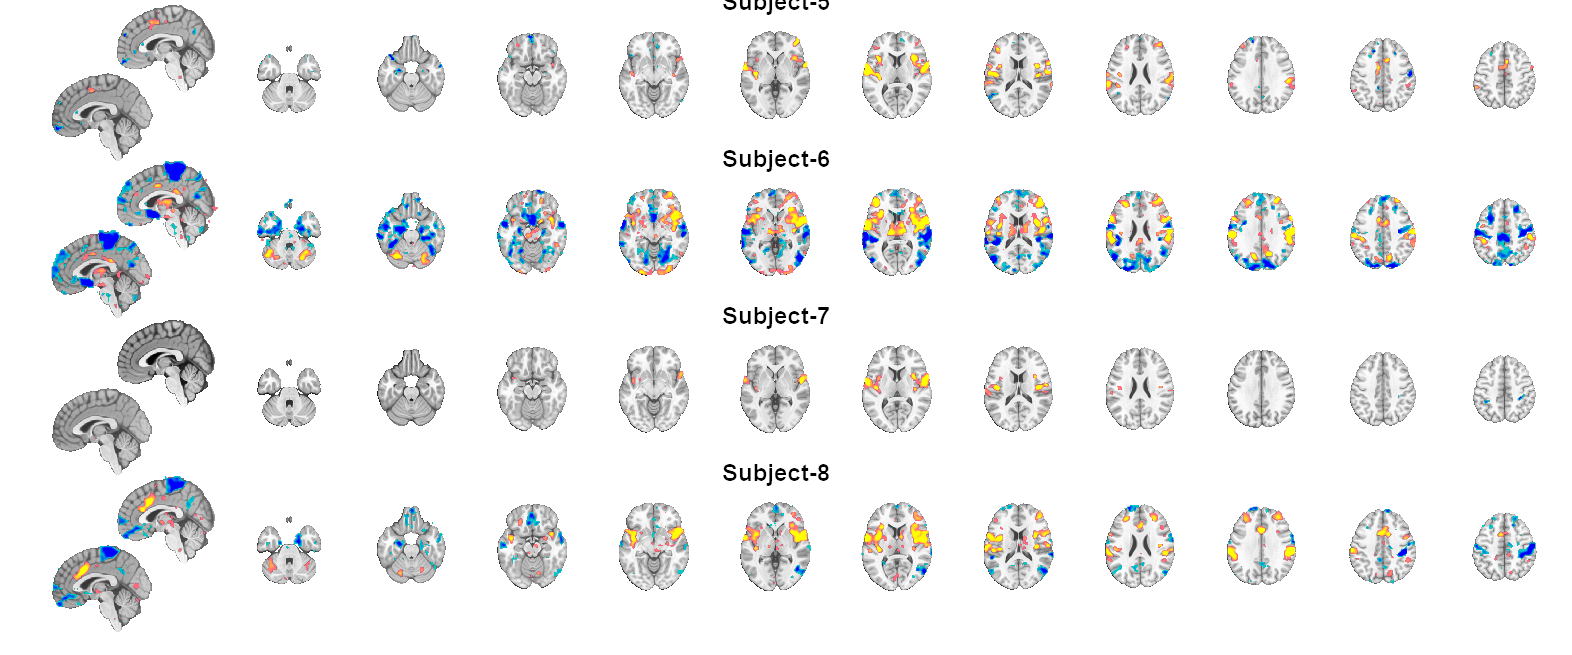

Image   1 FDR q < 0.050 threshold is 0.014886

Image   1
 89 contig. clusters, sizes   1 to 23672
Positive effect: 11587 voxels, min p-value: 0.00000000
Negative effect: 15704 voxels, min p-value: 0.00000000
Grouping contiguous voxels:  89 regions


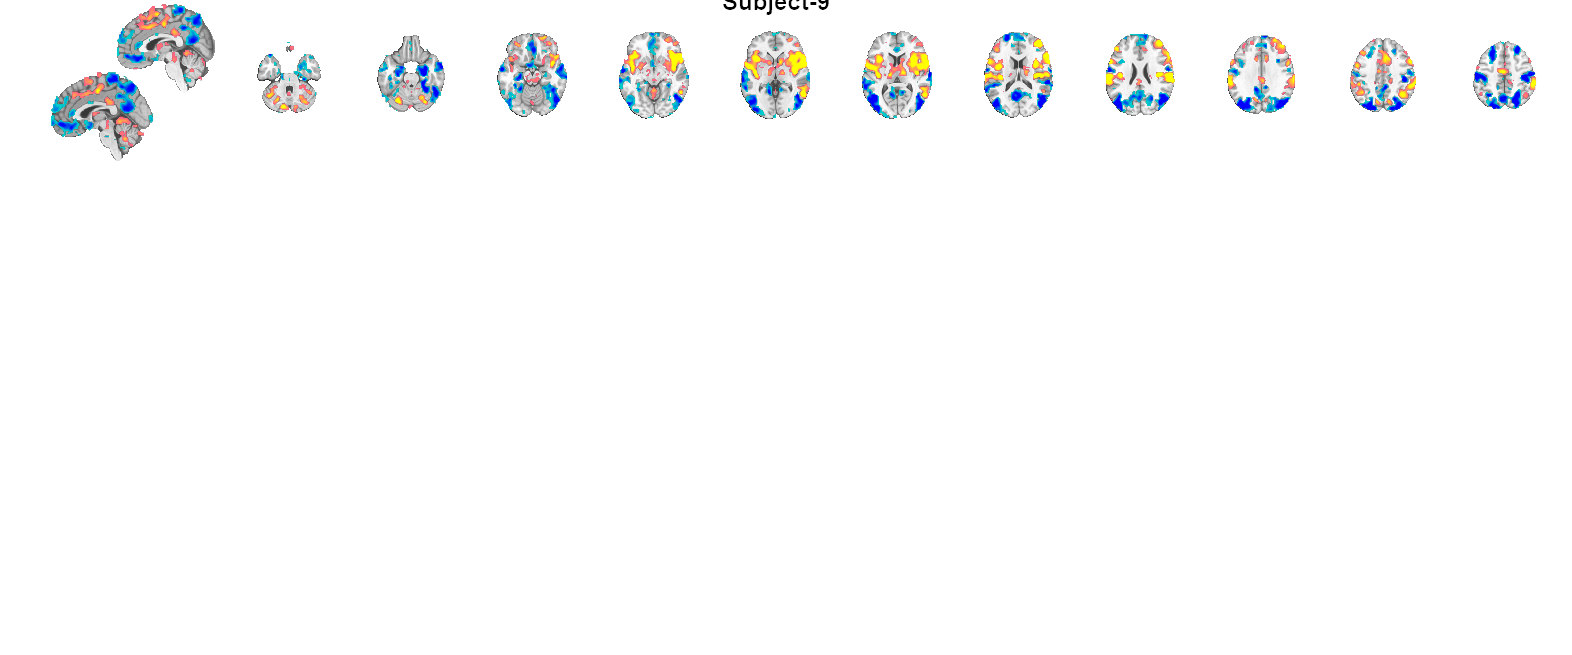

compareMaps(hw_vox_t, strcat('Subject-', cellstr(num2str((1:9)'))));

## Supplementary Figure 5: Participant-level imagined pain contrast (Imagine-Warm)

Compressed NIfTI files are not supported.
Image   1 FDR q < 0.050 threshold is 0.004811

Image   1
131 contig. clusters, sizes   1 to 1668
Positive effect: 2665 voxels, min p-value: 0.00000000
Negative effect: 6156 voxels, min p-value: 0.00000000
Grouping contiguous voxels: 131 regions
Image   1 FDR q < 0.050 threshold is 0.005038

Image   1
134 contig. clusters, sizes   1 to 2408
Positive effect: 4852 voxels, min p-value: 0.00000000
Negative effect: 4384 voxels, min p-value: 0.00000000
Grouping contiguous voxels: 134 regions
Image   1 FDR q < 0.050 threshold is 0.005697

Image   1
125 contig. clusters, sizes   1 to 5130
Positive effect: 3239 voxels, min p-value: 0.00000000
Negative effect: 7210 voxels, min p-value: 0.00000000
Grouping contiguous voxels: 125 regions
Image   1 FDR q < 0.050 threshold is 0.000001

Image   1
  1 contig. clusters, sizes   3 to   3
Positive effect:   0 voxels, min p-value: 0.00001520
Negative effect:   3 voxels, min p-value: 0.00000081
Grouping contiguous v

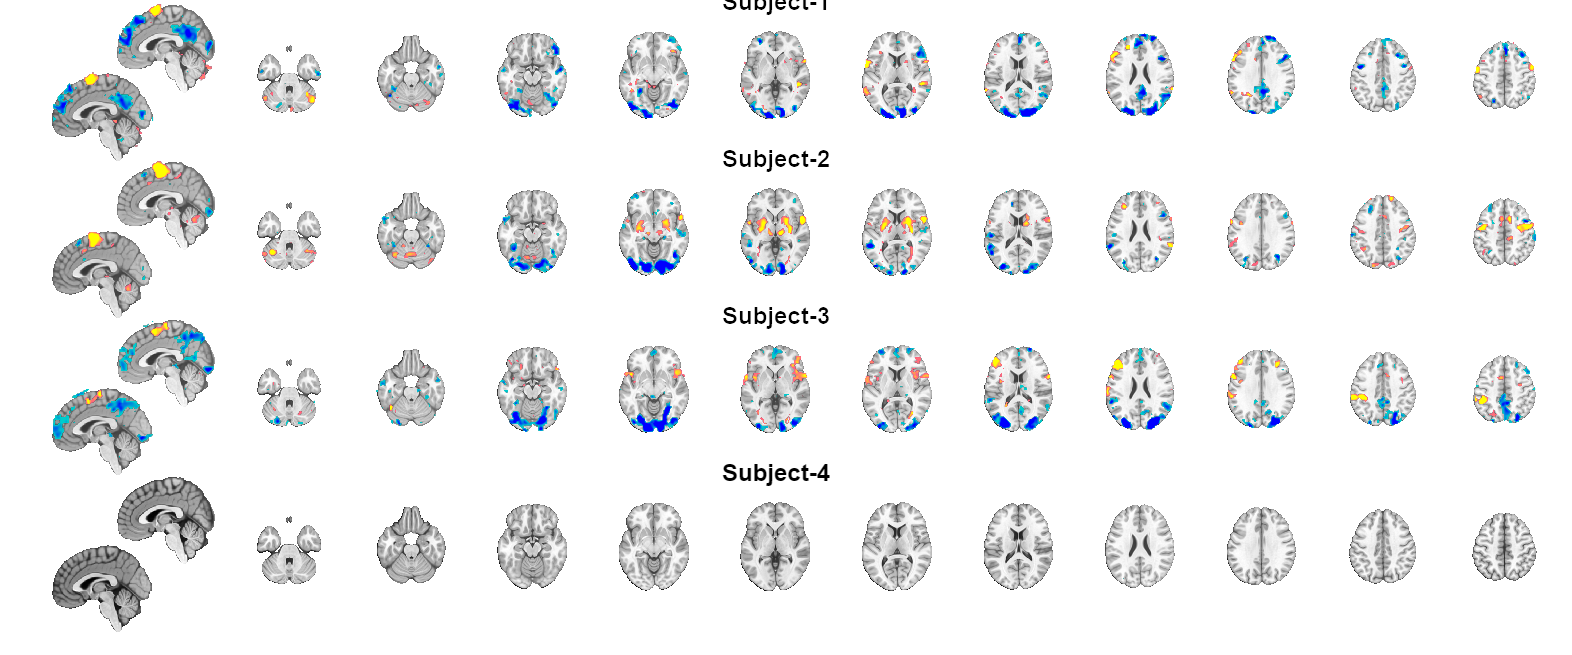

Image   1 FDR q < 0.050 threshold is 0.007622

Image   1
165 contig. clusters, sizes   1 to 4820
Positive effect: 8297 voxels, min p-value: 0.00000000
Negative effect: 5676 voxels, min p-value: 0.00000000
Grouping contiguous voxels: 165 regions
Image   1 FDR q < 0.050 threshold is 0.013115

Image   1
168 contig. clusters, sizes   1 to 19655
Positive effect: 6685 voxels, min p-value: 0.00000000
Negative effect: 17360 voxels, min p-value: 0.00000000
Grouping contiguous voxels: 168 regions
Image   1 FDR q < 0.050 threshold is 0.000205

Image   1
 23 contig. clusters, sizes   1 to 114
Positive effect: 110 voxels, min p-value: 0.00000098
Negative effect: 269 voxels, min p-value: 0.00000028
Grouping contiguous voxels:  23 regions
Image   1 FDR q < 0.050 threshold is 0.000000

Image   1
  0 contig. clusters, sizes     to    
Positive effect:   0 voxels, min p-value: 0.00003889
Negative effect:   0 voxels, min p-value: 0.00064930
Grouping contiguous voxels:   0 regions


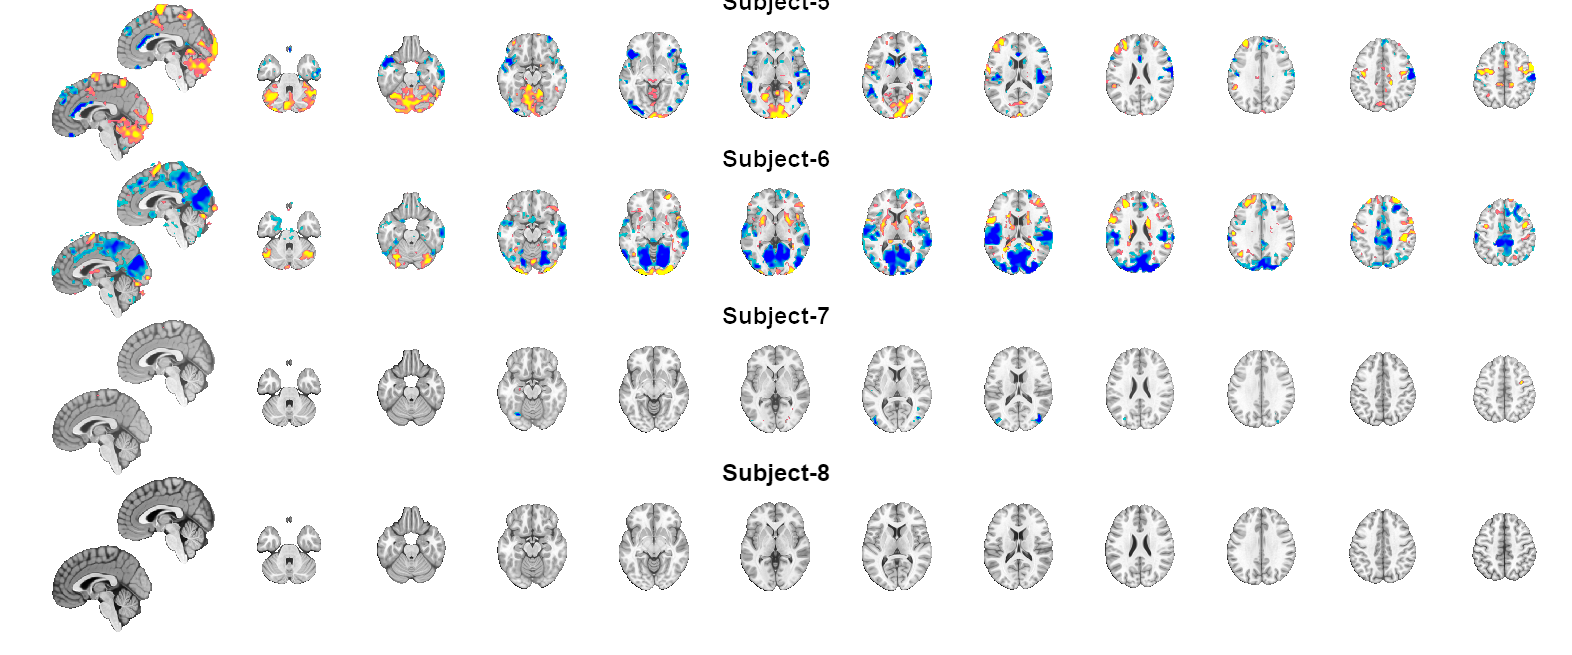

Image   1 FDR q < 0.050 threshold is 0.016938

Image   1
121 contig. clusters, sizes   1 to 24945
Positive effect: 16470 voxels, min p-value: 0.00000000
Negative effect: 14584 voxels, min p-value: 0.00000000
Grouping contiguous voxels: 121 regions


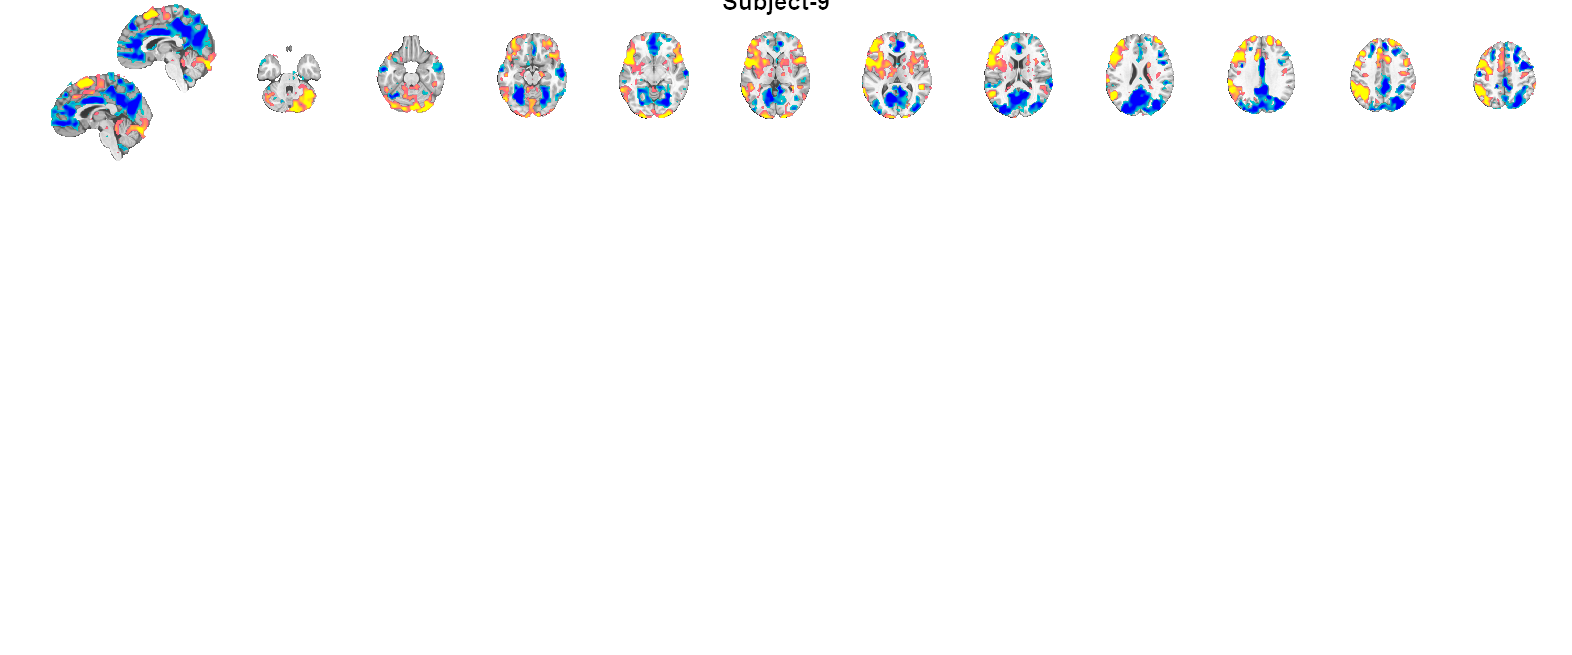

                        Region                        SubjectsWithPositiveActivations    SubjectsWithNegativeActivations                                                                                                                                                                                                                                                               label_descriptions                                                                                                                                                                                                                                                                                    labels                                       labels_2                                labels_3                                                                 labels_4                             

                        Region                        SubjectsWithPositiveActivations    SubjectsWithNegativeActivations                                                                                                                                                                                                                                                               label_descriptions                                                                                                                                                                                                                                                                                    labels                                       labels_2                                labels_3                                                                 labels_4                             

compareMaps(iw_vox_t, strcat('Subject-', cellstr(num2str((1:9)'))));

## Supplementary Figure 6

### Datasets

The datasets used to make the plots for Supplementary Figure S5 are in the following region-wise tables from CANlab2024:

- **HW5: **Describes the number of subjects exhibiting Hot-Warm Positive and Negative Activations encompassing at least 5% of the voxelwise region.

- **IW5: **Describes the number of subjects exhibiting Imagine-Warm Positive and Negative Activations encompassing at least 5% of the voxelwise region.

- **HWIW5: **Describes the number of subjects exhibiting Positive and Negative Activation overlap between Hot-Warm and Imagine-Warm contrasts, encompassing at least 5% of the voxelwise region for each contrast.

The columns **vals** are computed from the majority value: negative if there are more subjects with negative activations in that region, or positive if there are more subjects with positive activations in that region. The region is given a value in the **ties **column when there are an equal number of subjects exhibiting positive or negative activations.

disp(HW5);

                        Region                        SubjectsWithPositiveActivations    SubjectsWithNegativeActivations                                                                                                                                                                                                                                                               label_descriptions                                                                                                                                                                                                                                                                                    labels                                       labels_2                                labels_3                                                                 labels_4                             

Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits
Compressed NIfTI files are not supported.
    48



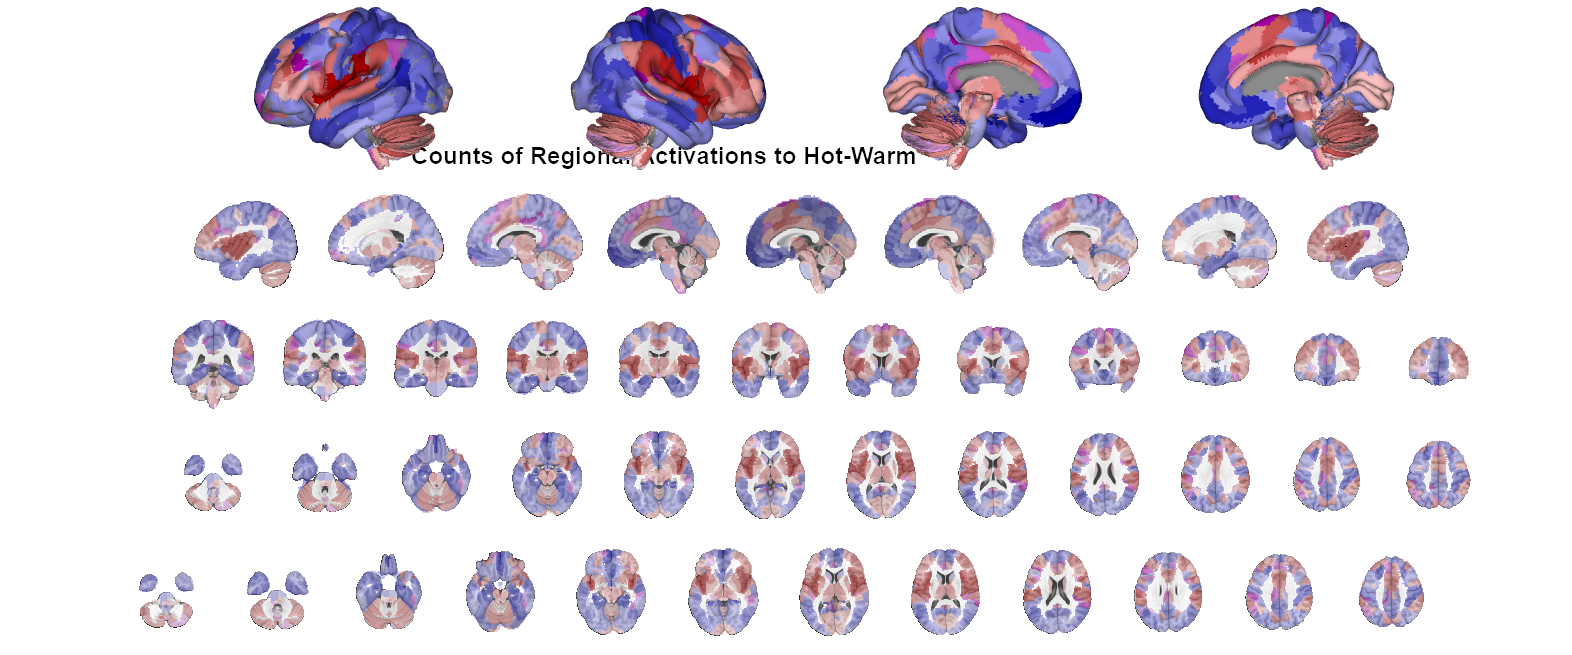

disp(IW5);
disp(HWIW5);

### Plot Count Maps

Final published maps in MRICroGL for easier plotting across 3 axes. Activations (Red), Deactivations (Blue), Tie (Purple)

#### Supplemental Figure 6A: Hot-Warm

Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.


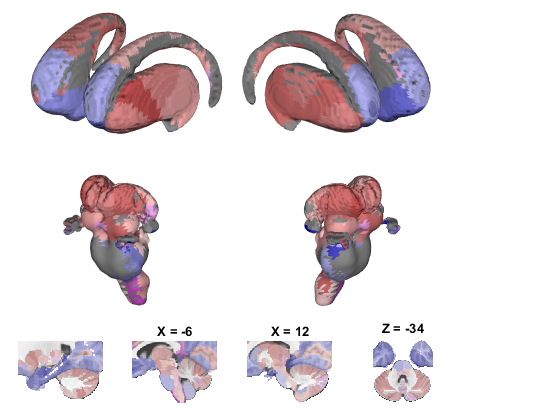

[HW5_fmri_data, HW5_ties]=plot_countmap(HW5, 'Counts of Regional Activations to Hot-Warm', ...
    .5, canlab2024, {'full hcp'});

plot_countmap(HW5, '', ...
    .5, canlab2024, {'subcortex compact'});

#### Supplemental Figure 6B: Imagine-Warm

Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits
Compressed NIfTI files are not supported.
    48



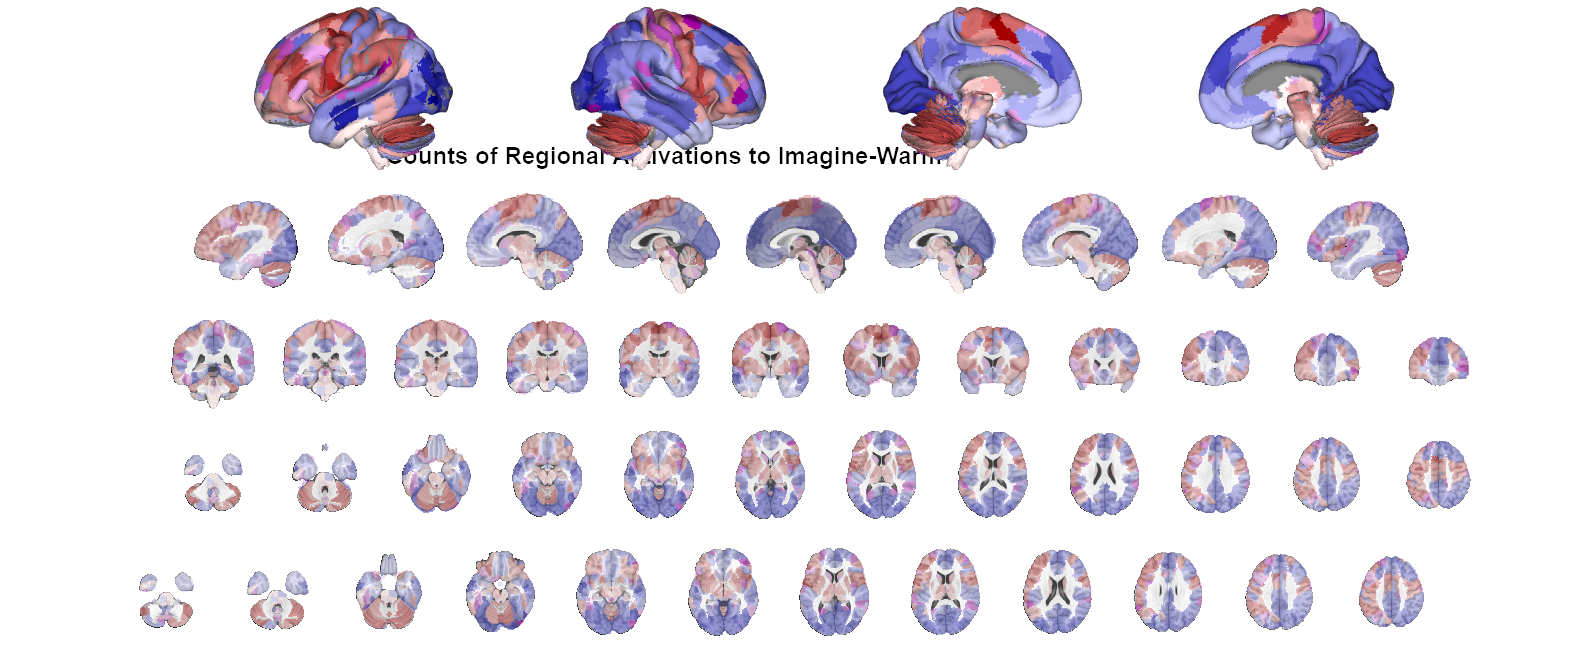

[IW5_fmri_data, IW5_ties]=plot_countmap(IW5, 'Counts of Regional Activations to Imagine-Warm', ...

Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.


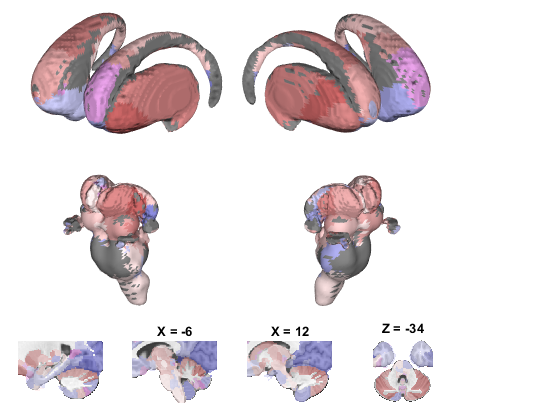

    .5, canlab2024, ...
    {'full hcp'});
plot_countmap(IW5, '', ...

    .5, canlab2024, ...
    {'subcortex compact'});

#### Supplemental Figure 6C: Hot-Warm & Imagine-Warm overlap

Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits
Compressed NIfTI files are not supported.
    48



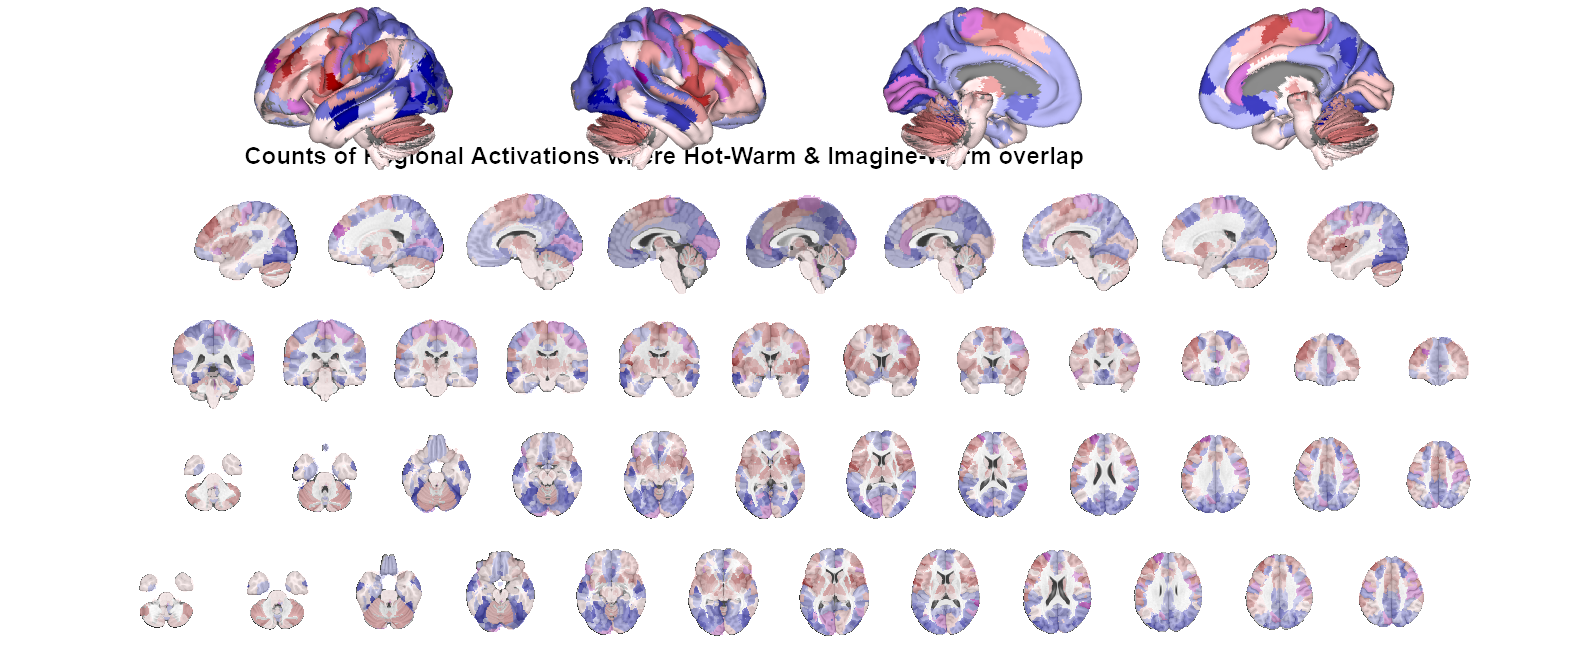

[HWIW5_fmri_data, HWIW5_ties]=plot_countmap(HWIW5, 'Counts of Regional Activations where Hot-Warm & Imagine-Warm overlap', ...

Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 519  Bit rate: 9.02 bits
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.


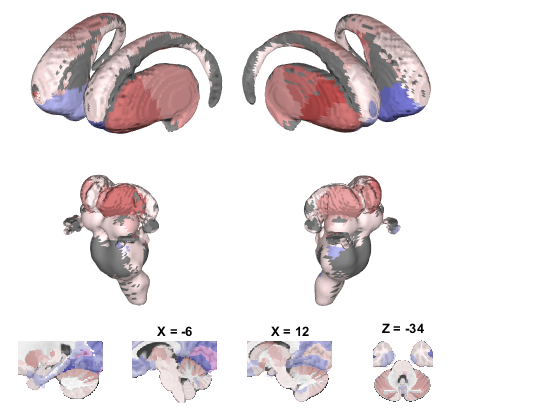

    .5, canlab2024, ...
    {'full hcp'});
plot_countmap(HWIW5, '', ...

    .5, canlab2024, ...
    {'subcortex compact'});

Writing: 
HW5l_posneg.nii


Writing: 
HW5_ties.nii


## Export Nifti Images for Plotting in MRICroGL

HW5_fmri_data.write('fname', 'HW5l_posneg.nii', 'overwrite');

Writing: 
IW5_posneg.nii


HW5_ties.write('fname', 'HW5_ties.nii', 'overwrite');

Writing: 
IW5_ties.nii


IW5_fmri_data.write('fname', 'IW5_posneg.nii', 'overwrite');

Writing: 
HWIW5_posneg.nii


IW5_ties.write('fname', 'IW5_ties.nii', 'overwrite');

Writing: 
HWIW5_ties.nii


HWIW5_fmri_data.write('fname', 'HWIW5_posneg.nii', 'overwrite');
HWIW5_ties.write('fname', 'HWIW5_ties.nii', 'overwrite');

function [grand_means, grand_se] = plot_subject_roi_means(tbl, unique_rois, unique_conditions, varargin)

    if ~isempty(varargin)
        subjID = varargin{1};
    else
        subjID = [];
    end

    unique_rois       = cellstr(unique_rois);
    unique_conditions = cellstr(unique_conditions);

    unique_subjects = unique(tbl.subject);    % numeric
    n_subjects      = numel(unique_subjects);
    n_conditions    = numel(unique_conditions);

    subject_colors = hsv(10);
    subject_colors = subject_colors([1:2,4:end], :);

    figure('Position', [0, 0, 2560, 1200]);

    grand_means = cell(numel(unique_rois),1);
    grand_se    = cell(numel(unique_rois),1);

    for r = 1:numel(unique_rois)
        roi = unique_rois{r};
        roi_data = tbl(strcmp(tbl.ROI, roi), :);

        grand_means{r} = zeros(1, n_conditions);
        grand_se{r}    = zeros(1, n_conditions);

        % ----- grand means / SE across subjects -----
        for c = 1:n_conditions
            cond = unique_conditions{c};
            cond_data = roi_data(strcmp(roi_data.condition, cond), :);

            grand_means{r}(c) = mean(cond_data.mean, 'omitnan');
            grand_se{r}(c)    = std(cond_data.mean, 'omitnan') / sqrt(height(cond_data));
        end

        % ----- plotting -----
        subplot(2, ceil(numel(unique_rois) / 2), r);
        hold on;
        title(roi, 'Interpreter', 'none');

        x_positions = 1:n_conditions;

        % subject-level lines + floating error bars
        for s = 1:n_subjects
            sid = unique_subjects(s);

            subj_data = roi_data(roi_data.subject == sid, :);  % numeric comparison

            if isempty(subj_data)
                continue;
            end

            % reorder rows to match unique_conditions
            [tf, idx_in_sub] = ismember(unique_conditions, subj_data.condition);
            valid   = tf;
            order   = idx_in_sub(valid);
            if isempty(order)
                continue;
            end

            subj_data_ord = subj_data(order, :);
            x_jitter = x_positions(valid) + randn(1, sum(valid)) * 0.15;

            if ismember(s, subjID)
                lw = 3; ms = 18; cap = 15;
            else
                lw = 1; ms = 18; cap = 10;
            end

            plot(x_jitter, subj_data_ord.mean, '-', 'Color', subject_colors(s,:), 'LineWidth', lw);
            for ii = 1:height(subj_data_ord)
                errorbar(x_jitter(ii), subj_data_ord.mean(ii), subj_data_ord.ste(ii), '.', ...
                    'Color', subject_colors(s,:), 'MarkerSize', ms, 'CapSize', cap, 'LineWidth', lw);
            end
        end

        % grand mean bars + SE
        b = bar(x_positions, grand_means{r}, 'FaceAlpha', 0.5, ...
                'EdgeColor', 'k', 'LineWidth', 1.5);
        b.FaceColor = 'flat';
        b.CData     = [1 0 0; 0 0 1];   % HotWarm = red, ImagineWarm = blue

        errorbar(x_positions, grand_means{r}, grand_se{r}, 'k', ...
                 'linestyle', 'none', 'LineWidth', 1.5);

        xticks(x_positions);
        xticklabels(unique_conditions);
        ylabel('Estimate');

        yticklabels(arrayfun(@(y) sprintf('%.2f', y), yticks, 'UniformOutput', false));
    end
end


function roi_stats = roi_stats_from_beta(image, roi_mask, df)

    % Extract voxel values
    % beta     = image.b(roi_mask);
    % ste      = image.b_ste(roi_mask);
    
    keyboard
    image.removed_voxels = [];
    image.removed_images = [];
    % [beta_roi, ~, ~, ~, ~, ~, ste] = extract_data(roi_mask, fmri_data(image.b));

    roi_mask = resample_space(fmri_data(image), roi_mask)

    [beta_roi, ~, ~, ~, ~, ~, ste] = apply_parcellation(roi_mask, fmri_data(image));
    
    % ROI-level beta
    % beta_roi = mean(beta, 'omitnan');
    
    % ROI-level SE
    SE_roi   = sqrt(sum(image.b.ste.^2)) / numel(image.b.ste);
    
    % T statistic
    t_roi    = beta_roi / SE_roi;
    
    % Two-sided p-value
    p_roi    = 2*(1 - tcdf(abs(t_roi), df));
    
    % significance
    sig      = p_roi < 0.05;
    
    roi_stats = struct( ...
        'beta', beta_roi, ...
        'SE',   SE_roi, ...
        't',    t_roi, ...
        'p',    p_roi, ...
        'sig',  sig);
end



function [condition_tbl l3_tbl_r net_tbl_r]= createConditionTable(img, thresh)
    % Function to create a condition table
    % Inputs:
    %   atlas_obj: Atlas object to be used
    %   condition_name: Name of the condition (e.g., 'warm')
    % Replace 'warm' with 'condition_name' in all relevant places
    % For example:
    % [condition_postbl1, condition_negtbl1, condition_tbl_r, ~, ~, ~, full_tbl] = ...
    %     condition_statsimg.table_of_atlas_regions_covered('atlas', atlas_obj, 'coverage', 1);

    canlab2024=load_atlas('canlab2024');
    canlab2024.probability_maps = [];
    canlab2018 = load_atlas('canlab2018');
    nets = canlab2018.labels_2;
    labels = canlab2024.labels;
    
    % iter over canlab2024 labels and find the corresponding network label fro
    % canlab2018f
    sorted_nets = cell(1,length(labels));
    for i = 1:length(labels)
        if contains(labels{i},'Ctx')
            sorted_nets{i} = nets{strcmp(canlab2018.labels,labels{i})};
        else
            sorted_nets{i} = 'subctx';
        end
    end
    canlab2024.labels_5=sorted_nets;

    canlab2024_l3=canlab2024.downsample_parcellation('labels_3'); % This will compress all like-named regions
    canlab2024_net=canlab2024.downsample_parcellation('labels_5'); % This will compress all regions into their constituent networks
    canlab2024_net.labels_2=canlab2024_net.labels; % This will compress all regions into their constituent networks
    % canlab2024_net.labels=canlab2024_net.labels_2; % This will compress all regions into their constituent networks
    
    canlab2024_2=canlab2024;
    canlab2024_2.labels=canlab2024.labels_3;
    canlab2024_3=canlab2024;
    canlab2024_3.labels=canlab2024.labels_5;
    
    % Interpretation:
    % sortrows(warm_postbl1, {'mean_in_region'}, 'descend');
    % sortrows(warm_negtbl1, {'mean_in_region'}, 'ascend');
    % table_simple(warm_tbl_r)
    
    [postbl1, negtbl1, tbl_r, ~, ~, ~, full_tbl]=img.table_of_atlas_regions_covered('atlas', canlab2024, 'coverage', thresh); % This gets us the regions and their coverage
    [postbl_l3, negtbl_l3, l3_tbl_r]=img.table_of_atlas_regions_covered('atlas', canlab2024_l3, 'coverage', thresh); % This gets us the regions and their coverage
    [postbl_net, negtbl_net, net_tbl_r]=img.table_of_atlas_regions_covered('atlas', canlab2024_net, 'coverage', thresh); % This gets us the regions and their coverage
    
    disp('Region Table');
    l3_tbl_r;
    disp('Network Table');
    net_tbl_r;

    [postbl2, negtbl2, ~, ~, ~, ~, full_tbl]=img.table_of_atlas_regions_covered('atlas', canlab2024_2, 'coverage', thresh); % This gets us the regions and their coverage
    [postbl3, negtbl3, ~, ~, ~, ~, full_tbl]=img.table_of_atlas_regions_covered('atlas', canlab2024_3, 'coverage', thresh); % This gets us the regions and their coverage
    
    % Formatting
    [~,pos, neg]=table_simple(tbl_r);
    
    postbl=horzcat(postbl1, postbl2.Region, postbl3.Region, pos(:,2:end-1)); % Append Volume and XYZ
    negtbl=horzcat(negtbl1, negtbl2.Region, negtbl3.Region, neg(:,2:end-1));
    postbl.Properties.VariableNames{8} = 'modal_name';
    postbl.Properties.VariableNames{10} = 'network';
    
    negtbl.Properties.VariableNames{8} = 'modal_name';
    negtbl.Properties.VariableNames{10} = 'network';
    
    % Interpretation 2
    sortrows(postbl, {'mean_in_region'}, 'descend');
    sortrows(negtbl, {'mean_in_region'}, 'ascend');
    
    sortrows(postbl, {'modal_name'}, 'ascend');
    sortrows(negtbl, {'modal_name'}, 'ascend');
    
    sortrows(postbl, {'network'}, 'ascend');
    sortrows(negtbl, {'network'}, 'ascend');
    
    % Final Formatting
    % Concatenate Tables
    tbl=vertcat(postbl, negtbl);
    % Rearrange columns
    tbl=tbl(:, {'modal_name', 'Region', 'network', 'Volume', 'Voxels_in_region', 'Coverage', 'XYZ' 'mean_in_region', 'max_abs_in_region'});
    % Rearrange rows
    sortrows(tbl, 'mean_in_region', 'descend');

    % Manually determine which modal_name keywords should be clustered together.
    sortrows(tbl, 'modal_name', 'ascend');
    % Insula, Putamen, Somatomotor, Thalamus, vlPFC, Mid, Medulla,
    % Cere/Vermis, CAU, VStriatum, parietal_inferior, parietal_TPOJ
    kw={'Hippo', 'Amy', 'insula', 'somato', 'Thal', 'cingulate_vlPFC', 'cingulate_dlPFC', ...
    'cingulate_ACC', 'cingulate_posterior', 'cingulate_ventral', 'parietal_superior', ...
    'parietal_inferior', 'parietal_TPOJ', 'temporal', 'auditory_early', 'auditory_association',...
     'visual_early', 'visual_ventral', 'visual_dorsal', 'visual_MT', 'cere', 'vermis', 'Mid', ...
    'VStriatum', 'Medulla', 'Pons', 'PUT', 'GP', 'CAU'};
    t=table;
    for i = 1:numel(kw)
        t=[t;sortrows(tbl(contains(tbl.modal_name,kw{i}),:), {'modal_name','Coverage'}, {'ascend','descend'})];
    end
    tbl=t;

    % Add a hemisphere column
    hemi = cellfun(@(x) x(end), tbl.modal_name, 'UniformOutput', false);
    for i = 1:length(hemi)
        if ~(hemi{i}(end) == 'L' || hemi{i}(end) == 'R')
            hemi{i} = '';
        end
    end
    hemi=table(hemi);
    condition_tbl=[hemi, tbl];


end


function [overlapRows uniqueRows]= overlapRegions(tbl1, tbl2)




    % Find rows in imag_tbl that overlap with hot_tbl based on 'modal_name' and 'Region'
    overlapRows = innerjoin(tbl2, tbl1, 'Keys', {'modal_name', 'Region'});
    
    % Extract the key columns from both tables
    keys_tbl2 = tbl2(:, {'modal_name', 'Region'});
    keys_tbl1 = tbl1(:, {'modal_name', 'Region'});
    
    % Convert tables to arrays of strings for comparison (if they are not already strings)
    keys_tbl2_array = table2array(keys_tbl2);
    keys_tbl1_array = table2array(keys_tbl1);

    % Flatten the cell arrays for direct comparison if they are not simple numeric or string arrays
    keys_tbl2_flat = strcat(keys_tbl2_array(:,1), '_', keys_tbl2_array(:,2));
    keys_tbl1_flat = strcat(keys_tbl1_array(:,1), '_', keys_tbl1_array(:,2));

    % Use ismember to find non-matching rows
    [isUnique, ~] = ismember(keys_tbl2_flat, keys_tbl1_flat);
    
    % The rows unique to imag_tbl are those for which isUnique is false
    uniqueRowsIdx = ~isUnique; % Notice the negation to find non-matches
    
    % Extract the unique rows from imag_tbl based on the corrected index
    uniqueRows = tbl2(uniqueRowsIdx, :);
end


function joinedTable= bigOverlap(tbl1, tbl2)
    % Includes all rows from both tables with NaN or empty where there is
    % no match.


    % Add a column to tbl1 to indicate original row order
    tbl1.RowOrder = (1:height(tbl1))';
    
    % Perform the outer join
    joinedTable = outerjoin(tbl1, tbl2, 'Keys', {'modal_name', 'Region'}, 'MergeKeys', true);
    
    % Sort the joined table by the RowOrder column to preserve the original order of tbl1
    joinedTable = sortrows(joinedTable, 'RowOrder');
    
    % Remove the RowOrder column if it's no longer needed
    joinedTable.RowOrder = [];

end

function [ final_table, pos_counts, neg_counts, reg_count_tbl ] = ...
    regionSubjectSummary(hw_voxel_conj, atlasObj, subjects, coverageThresh)
% regionSubjectSummary   Use only tpos/tneg to build your tables
%
% [final_table,pos_counts,neg_counts,HW_reg_count_tbl] = ...
%   regionSubjectSummary(hw_voxel_conj, atlasObj, subjects, coverageThresh);
%
% Inputs:
%   hw_voxel_conj  – 1×N cell of statistic_image objects
%   atlasObj       – atlas (e.g. canlab2024_2)
%   subjects       – 1×N cell of subject IDs
%   coverageThresh – scalar percent (default 0)
%
% Outputs:
%   final_table      – subject×region table (changes with coverageThresh)
%   pos_counts       – [Region,Counts,Percentage] for positives
%   neg_counts       – [Region,Counts,Percentage] for negatives
%   reg_count_tbl – [Region,SubjectsWithPositiveActivations,SubjectsWithNegativeActivations]

if nargin < 4
    coverageThresh = 0;
end
coverageThresh = max(coverageThresh, 0);

nSub = numel(subjects);
tpos = cell(nSub, 1);
tneg = cell(nSub, 1);

%% 1) Grab only the two tables (pos & neg) per subject
for i = 1:nSub
    disp(subjects{i});
    try
        [tpos{i}, tneg{i}] = hw_voxel_conj{i} ...
            .table_of_atlas_regions_covered( ...
                'atlas_obj', atlasObj, ...
                'coverage',  coverageThresh );
    catch
        disp('  No Regions to Display');
        tpos{i} = table();
        tneg{i} = table();
    end
end

%% 2) Build final_table from tpos & tneg using outerjoin per subject
subTables = cell(nSub, 1);

for i = 1:nSub
    posT = tpos{i};
    negT = tneg{i};

    if isempty(posT) && isempty(negT)
        continue;
    end

    % Ensure Region is string for reliable matching
    if ~isempty(posT)
        posT.Region = string(posT.Region);
    end
    if ~isempty(negT)
        negT.Region = string(negT.Region);
    end

    % Full outer join on Region (union of all regions for this subject)
    if ~isempty(posT) && ~isempty(negT)
        perSub = outerjoin(posT, negT, ...
            'Keys',       'Region', ...
            'MergeKeys',  true, ...
            'Type',       'full', ...
            'Suffixes',   {'_pos', '_neg'});
    elseif ~isempty(posT)
        perSub = posT;
        % fabricate neg columns of zeros if needed later
        perSub.Coverage_neg          = zeros(height(perSub),1);
        perSub.Voxels_in_region_neg  = zeros(height(perSub),1);
        perSub.Atlas_index_number_neg = zeros(height(perSub),1);
        perSub.mean_in_region_neg    = zeros(height(perSub),1);
        perSub.max_abs_in_region_neg = zeros(height(perSub),1);
    else % only negT
        perSub = negT;
        perSub.Coverage_pos          = zeros(height(perSub),1);
        perSub.Voxels_in_region_pos  = zeros(height(perSub),1);
        perSub.Atlas_index_number_pos = zeros(height(perSub),1);
        perSub.mean_in_region_pos    = zeros(height(perSub),1);
        perSub.max_abs_in_region_pos = zeros(height(perSub),1);
    end

    % Ensure all expected columns exist (in case table_of_atlas_regions_covered changed)
    perSub = ensure_stat_cols(perSub);

    % Build the per-subject row block in the final schema
    nR = height(perSub);
    subTbl = table;

    subTbl.Subject = repmat(string(subjects{i}), nR, 1);
    % You were previously using Region as ModalLabelDescriptions
    subTbl.ModalLabelDescriptions = perSub.Region;

    % Positive side
    subTbl.Pos_Region             = perSub.Region;
    subTbl.Pos_Coverage           = perSub.Coverage_pos;
    subTbl.Pos_Voxels_in_region   = perSub.Voxels_in_region_pos;
    subTbl.Pos_Atlas_index_number = perSub.Atlas_index_number_pos;
    subTbl.Pos_mean_in_region     = perSub.mean_in_region_pos;
    subTbl.Pos_max_abs_in_region  = perSub.max_abs_in_region_pos;

    % Negative side (same Region key, different stats)
    subTbl.Neg_Region             = perSub.Region;
    subTbl.Neg_Coverage           = perSub.Coverage_neg;
    subTbl.Neg_Voxels_in_region   = perSub.Voxels_in_region_neg;
    subTbl.Neg_Atlas_index_number = perSub.Atlas_index_number_neg;
    subTbl.Neg_mean_in_region     = perSub.mean_in_region_neg;
    subTbl.Neg_max_abs_in_region  = perSub.max_abs_in_region_neg;

    subTables{i} = subTbl;
end

% Concatenate across subjects (drop empties)
subTables = subTables(~cellfun(@isempty, subTables));
if isempty(subTables)
    final_table = table();
else
    final_table = vertcat(subTables{:});
end

%% 3) Positive counts
pos_counts = region_counts(final_table.Pos_Region);

%% 4) Negative counts
neg_counts = region_counts(final_table.Neg_Region);

%% 5) Build HW_reg_count_tbl aligned to the atlas
canlab2024_r = atlas2region(atlasObj);
regionNames  = string({canlab2024_r.shorttitle})';
nR           = numel(regionNames);

posVec = zeros(nR,1);
negVec = zeros(nR,1);

[tfP, locP] = ismember(regionNames, pos_counts.Region);
posVec(tfP) = pos_counts.Counts(locP(tfP));

[tfN, locN] = ismember(regionNames, neg_counts.Region);
negVec(tfN) = neg_counts.Counts(locN(tfN));

reg_count_tbl = table( ...
    regionNames, posVec, negVec, ...
    'VariableNames', { ...
        'Region', ...
        'SubjectsWithPositiveActivations', ...
        'SubjectsWithNegativeActivations'} );
end

function out = region_counts(regionVar)
    % Build [Region,Counts,Percentage] from a region column
    regionStr = string(regionVar);
    if isempty(regionStr)
        out = table(string.empty(0,1), zeros(0,1), zeros(0,1), ...
            'VariableNames', {'Region','Counts','Percentage'});
        return;
    end

    G = groupcounts(regionStr);  % table: Group, GroupCount
    nTotal = numel(regionStr);

    out = table( ...
        G.Group, ...
        G.GroupCount, ...
        100 * G.GroupCount / nTotal, ...
        'VariableNames', {'Region','Counts','Percentage'});
end

function T = ensure_stat_cols(T)
    % Make sure the outerjoined table has all expected *_pos / *_neg columns.
    % This protects you if table_of_atlas_regions_covered changes slightly.

    colNames = T.Properties.VariableNames;

    % If we don't have suffixes, assume this is a pure pos or pure neg table
    % and fabricate the missing side.
    needsPos = ~any(endsWith(colNames, '_pos'));
    needsNeg = ~any(endsWith(colNames, '_neg'));

    baseCols = {'Coverage', 'Voxels_in_region', 'Atlas_index_number', ...
                'mean_in_region', 'max_abs_in_region'};

    if needsPos
        for k = 1:numel(baseCols)
            namePos = [baseCols{k} '_pos'];
            if ismember(baseCols{k}, colNames)
                T.(namePos) = T.(baseCols{k});
            else
                T.(namePos) = zeros(height(T),1);
            end
        end
    end

    if needsNeg
        for k = 1:numel(baseCols)
            nameNeg = [baseCols{k} '_neg'];
            if ismember(baseCols{k}, colNames)
                T.(nameNeg) = T.(baseCols{k});
            else
                T.(nameNeg) = zeros(height(T),1);
            end
        end
    end

    % If we do have some *_pos / *_neg already, also ensure all baseCols exist
    for k = 1:numel(baseCols)
        namePos = [baseCols{k} '_pos'];
        nameNeg = [baseCols{k} '_neg'];
        if ~ismember(namePos, colNames)
            T.(namePos) = zeros(height(T),1);
        end
        if ~ismember(nameNeg, colNames)
            T.(nameNeg) = zeros(height(T),1);
        end
    end
end

function tbl = format_condition_table(tbl)
    tbl.modal_name = format_strings_for_legend(tbl.modal_name);
    tbl.Region     = format_strings_for_legend(tbl.Region);
    tbl.network    = format_strings_for_legend(tbl.network);
end

function stats_tbl = build_stats_table(OUT, canlab2024, prefix)
    % Generic helper for HW / IW stats tables
    stats_tbl = table(canlab2024.labels', OUT.tscores, OUT.pvalues, OUT.sig_q05, ...
        'VariableNames', {'Region', 'T', 'P', 'FDR Sig.'});

    % Add prefixed vars while retaining original fields if desired
    stats_tbl.([prefix '_T'])        = stats_tbl.T;
    stats_tbl.([prefix '_P'])        = stats_tbl.P;
    stats_tbl.([prefix ' FDR Sig.']) = stats_tbl.("FDR Sig.");
end

function canlab2024 = add_network_labels_from_2018(canlab2024, canlab2018)
    nets   = canlab2018.labels_2;
    labels = canlab2024.labels;

    sorted_nets = cell(size(labels));
    for i = 1:numel(labels)
        if contains(labels{i}, 'Ctx')
            match = strcmp(canlab2018.labels, labels{i});
            if any(match)
                sorted_nets{i} = nets{match};
            else
                sorted_nets{i} = 'unknown';
            end
        else
            sorted_nets{i} = 'subctx';
        end
    end

    canlab2024.labels_5 = sorted_nets;
    % label_table is updated via the atlas object’s own machinery; if not,
    % you can rebuild it here as needed.
end

function tbl = add_vals_and_ties(tbl)
    % vals: +pos where pos>neg, –neg where neg>pos, 0 on ties
    pos = tbl.SubjectsWithPositiveActivations;
    neg = tbl.SubjectsWithNegativeActivations;

    tbl.vals = (pos >  neg) .* pos ...
             - (neg >  pos) .* neg;

    % ties: count only when pos==neg
    tbl.ties = (pos == neg) .* pos;
end

function [posneg_img, tie_img] = plot_countmap(tbl, title_str, ...
    trans_value, canlab2024, montage_views)

    w = warning ('off','all');

    % Define base & full colors once
    base_red    = [1.00, 0.90, 0.90];   full_red    = [0.60, 0.00, 0.00];
    base_blue   = [0.90, 0.90, 1.00];   full_blue   = [0.00, 0.00, 0.60];
    base_purple = [1.00, 0.90, 1.00];   full_purple = [0.60, 0.00, 0.60];

    % 1) counts
    posregs = max(tbl.vals,  0);
    negregs = max(-tbl.vals, 0);
    tieregs = tbl.ties;

    % 1a.) Generate outputs
    posneg_img = canlab2024.assign_vals( ...
        'reg_names', tbl.Region, ...
        'vals',      posregs-negregs        ...
    );    
    tie_img = canlab2024.assign_vals( ...
        'reg_names', tbl.Region, ...
        'vals',      tieregs        ...
    );    

    % 2) dominant category per region
    [~, cat] = max([posregs, negregs, tieregs], [], 2);

    % 3) normalized intensities (protect against all-zero case)
    f_pos = safe_norm(posregs);
    f_neg = safe_norm(negregs);
    f_ti  = safe_norm(tieregs);

    % 4) per-region RGB ramp
    nR     = numel(tbl.Region);
    colors = zeros(nR,3);
    for i = 1:nR
        switch cat(i)
            case 1  % positive
                fi = f_pos(i);
                colors(i,:) = base_red    + fi*(full_red    - base_red);
            case 2  % negative
                fi = f_neg(i);
                colors(i,:) = base_blue   + fi*(full_blue   - base_blue);
            case 3  % tie
                fi = f_ti(i);
                colors(i,:) = base_purple + fi*(full_purple - base_purple);
        end
    end

    idx = (1:nR)';

    % Support one or multiple montage views
    for v = 1:numel(montage_views)
        figure;
        img = canlab2024.assign_vals( ...
            'reg_names', tbl.Region, ...
            'vals',      idx        ...
        );    
        o2 = img.montage( ...
            montage_views{v}, ...
            'sourcespace',   'MNI152NLin2009cAsym', ...
            'targetsurface', 'fsLR_32k', ...
            'trans',         'transvalue', trans_value, ...
            'indexmap',      colors,     ...
            'noverbose' ...
        );
        colorbar off;
        title_montage(o2, 1, title_str);
        % drawnow; snapnow;
        % close all;
    end
end

function f = safe_norm(x)
    mx = max(x);
    if mx == 0
        f = zeros(size(x));
    else
        f = x ./ mx;
    end
end

function check_orthogonality_and_balance(Xc, label)
    if nargin < 2, label = 'coding'; end

    G = Xc' * Xc;
    col_sums = sum(Xc,1);
    r = rank(Xc);
    expected_rank = size(Xc,2);

    fprintf('\n=== %s: orthogonality / balance check ===\n', label);
    disp('Dot products (X''X):');
    disp(G);
    fprintf('Column sums:\n'); disp(col_sums);
    fprintf('Rank: %d (expected %d)\n', r, expected_rank);

    off_diag = G - diag(diag(G));
    is_orthogonal = all(abs(off_diag(:)) < 1e-10);
    is_balanced   = all(abs(col_sums)   < 1e-10);

    if is_orthogonal
        fprintf(' -> Columns are orthogonal (within tolerance).\n');
    else
        fprintf(' -> Columns are NOT orthogonal.\n');
    end

    if is_balanced
        fprintf(' -> Columns are balanced (sum ~ 0).\n');
    else
        fprintf(' -> Columns are NOT balanced (summing columns to zero may be desirable).\n');
    end
    fprintf('========================================\n\n');
end